# Limpieza de datos

Primero se importan los datos con una función propia (timeTableCratorInador())

refrigerator_1 = timeTableCratorInador("Pool1/Sensor1-");
refrigerator_2 = timeTableCratorInador("Pool1/Sensor2-");
refrigerator_3 = timeTableCratorInador("Pool1/Sensor3-");
refrigerator_4 = timeTableCratorInador("Pool1/Sensor5-");
microwave_1 = timeTableCratorInador("Pool2/Sensor1-");
microwave_2 = timeTableCratorInador("Pool2/Sensor2-");
microwave_3 = timeTableCratorInador("Pool2/Sensor3-");
televition_1 = timeTableCratorInador("Pool3/Tele1-");
televition_2 = timeTableCratorInador("Pool3/Tele2-");
televition_3 = timeTableCratorInador("Pool3/Tele3-");

## Crear caso en que dos y tres aparatos esten funcionando al mismo tiempo

Separar en parte real y reactiva y sumarlas.

real = fp*aparente

reactiva = sqrt(aparente^2-real^2)

Modifique la función timeTableCratorInador para que genrara la corriente y potencia real y reactivia

Podemos tener 12 combinaciones diferentes, solo tomare 3 para mantener el valance.

refrigeratorMicrowave_1 = jointApplianceInador(refrigerator_2,microwave_1);
refrigeratorMicrowave_2 = jointApplianceInador(refrigerator_3,microwave_2);
refrigeratorMicrowave_3 = jointApplianceInador(refrigerator_4,microwave_3);

refrigeratorTelevition_1 = jointApplianceInador(refrigerator_2,televition_1);
refrigeratorTelevition_2 = jointApplianceInador(refrigerator_3,televition_2);
refrigeratorTelevition_3 = jointApplianceInador(refrigerator_4,televition_3);

microwaveTelevition_1 = jointApplianceInador(microwave_1,televition_1);
microwaveTelevition_2 = jointApplianceInador(microwave_2,televition_2);
microwaveTelevition_3 = jointApplianceInador(microwave_3,televition_3);

televitionRefrigeratorMicrowave_1 = jointApplianceInador(televition_1,refrigeratorMicrowave_1);
televitionRefrigeratorMicrowave_2 = jointApplianceInador(televition_2,refrigeratorMicrowave_2);
televitionRefrigeratorMicrowave_3 = jointApplianceInador(televition_3,refrigeratorMicrowave_3);

Removere valores reales y reactivos

refrigerator_1 = removevars(refrigerator_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_2 = removevars(refrigerator_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_3 = removevars(refrigerator_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigerator_4 = removevars(refrigerator_4, ["real_power" "reactive_power" "real_current" "reactive_current"]);

microwave_1 = removevars(microwave_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwave_2 = removevars(microwave_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwave_3 = removevars(microwave_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

televition_1 = removevars(televition_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
televition_2 = removevars(televition_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
televition_3 = removevars(televition_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

refrigeratorMicrowave_1 = removevars(refrigeratorMicrowave_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorMicrowave_2 = removevars(refrigeratorMicrowave_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorMicrowave_3 = removevars(refrigeratorMicrowave_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

refrigeratorTelevition_1 = removevars(refrigeratorTelevition_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorTelevition_2 = removevars(refrigeratorTelevition_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
refrigeratorTelevition_3 = removevars(refrigeratorTelevition_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

microwaveTelevition_1 = removevars(microwaveTelevition_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwaveTelevition_2 = removevars(microwaveTelevition_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
microwaveTelevition_3 = removevars(microwaveTelevition_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

televitionRefrigeratorMicrowave_1 = removevars(televitionRefrigeratorMicrowave_1, ["real_power" "reactive_power" "real_current" "reactive_current"]);
televitionRefrigeratorMicrowave_2 = removevars(televitionRefrigeratorMicrowave_2, ["real_power" "reactive_power" "real_current" "reactive_current"]);
televitionRefrigeratorMicrowave_3 = removevars(televitionRefrigeratorMicrowave_3, ["real_power" "reactive_power" "real_current" "reactive_current"]);

## Eliminación de datos atípicos

En la fase de limpieza de datos, se llevó a cabo un proceso para eliminar los valores atípicos presentes en los conjuntos de datos de los refrigeradores y microondas. Para lograr esto, se empleó el método de media móvil, una técnica estadística ampliamente utilizada en el análisis de series temporales.

Se estableció un factor de umbral (threshold factor) de 3, que se utilizó como criterio para identificar y descartar los datos considerados como outliers. Este factor permite definir un límite más allá del cual los valores se consideran anómalos en relación con el resto de la distribución de los datos.

Se optó por una ventana de 1 minuto.

La eliminación de datos atípicos mediante la media móvil y la aplicación de ventanas de tiempo específicas para cada tipo de dispositivo permitieron obtener conjuntos de datos más limpios y consistentes, preparándolos adecuadamente para las etapas posteriores del análisis y el tratamiento estadístico.

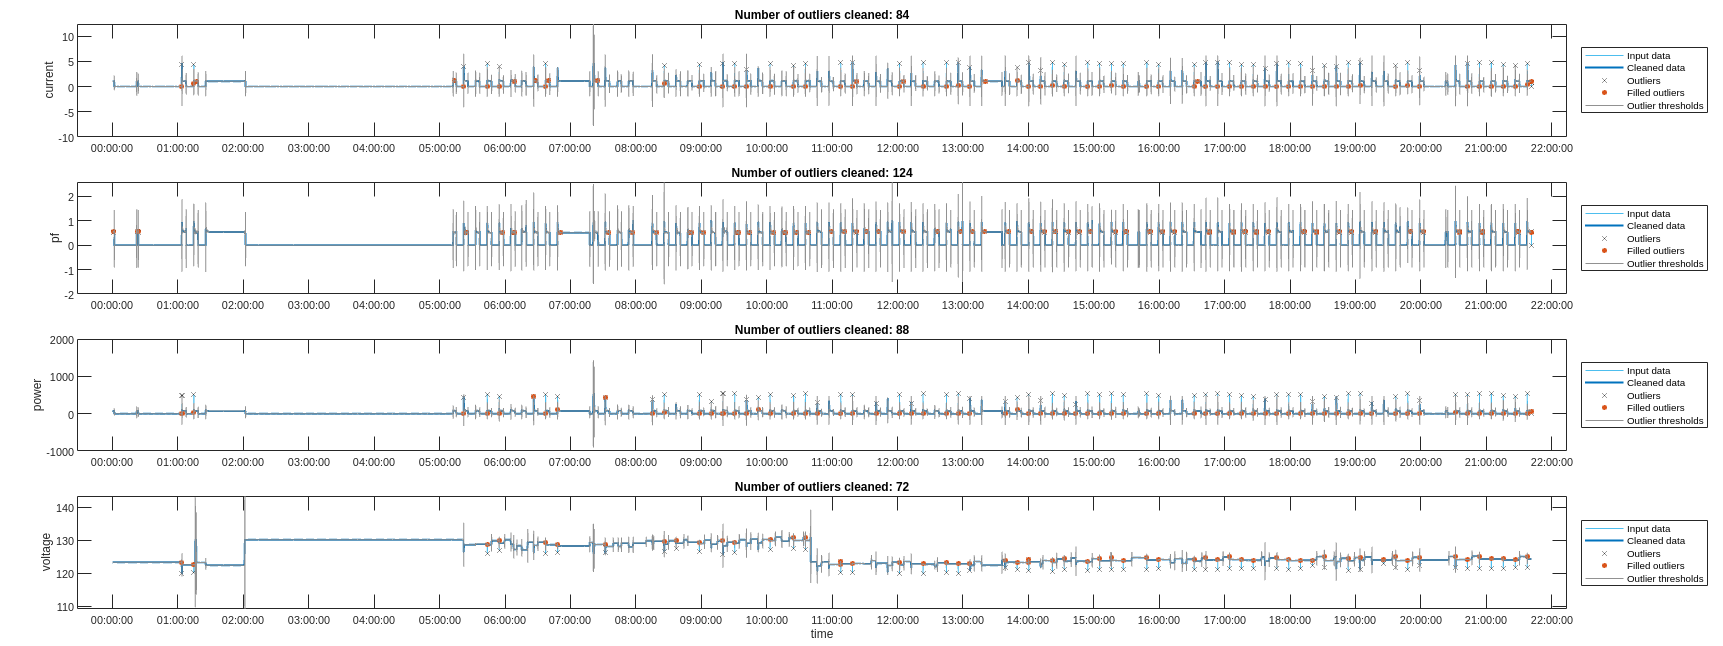

% Refrigerator_1
cleanedRefrigerator_1 = remueveOutliersInador(refrigerator_1);

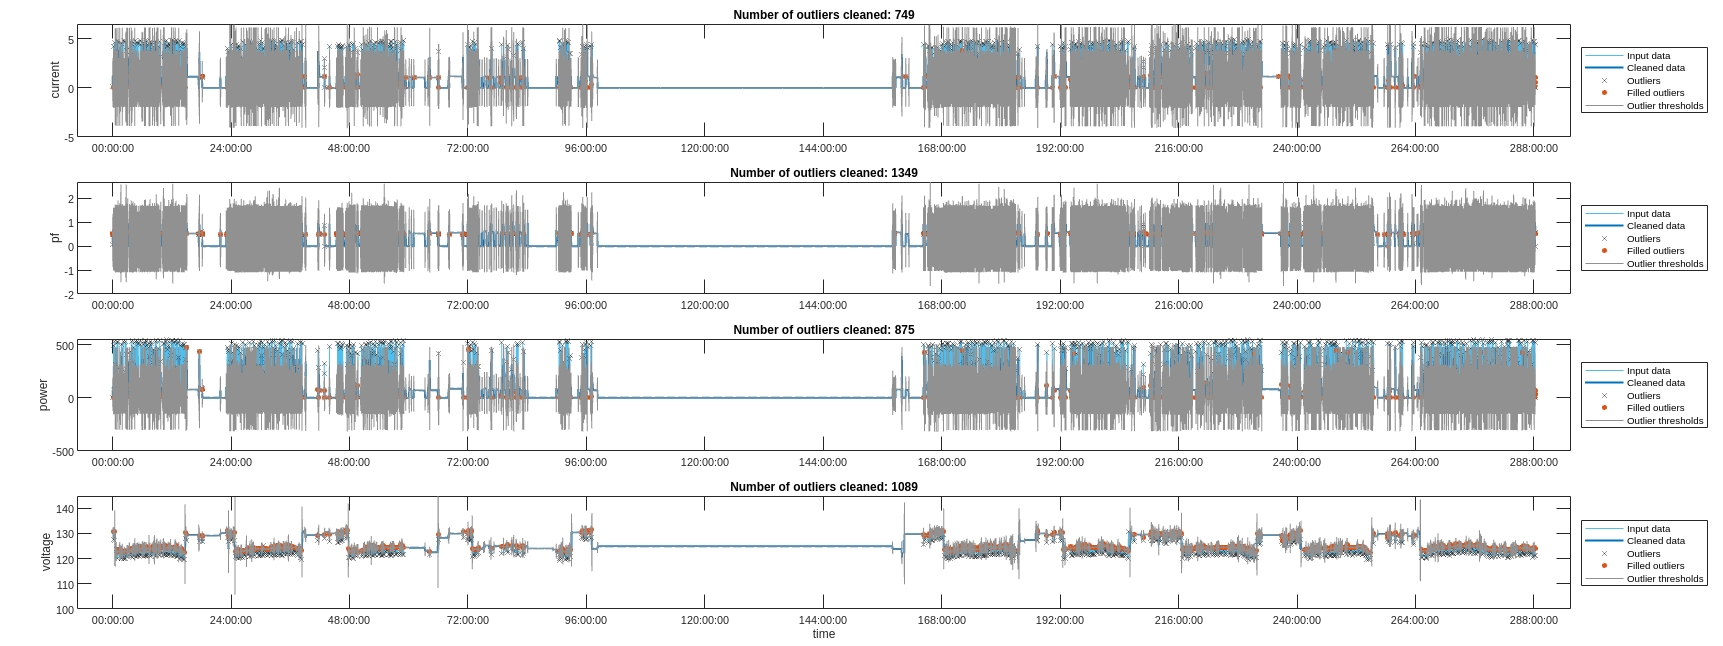


% Refrigerator_2
cleanedRefrigerator_2 = remueveOutliersInador(refrigerator_2,false);

% Refrigerator_3
cleanedRefrigerator_3 = remueveOutliersInador(refrigerator_3,false);

% Refrigerator_4
cleanedRefrigerator_4 = remueveOutliersInador(refrigerator_4,false);

% Microwave_1
cleanedMicrowave_1= remueveOutliersInador(microwave_1);

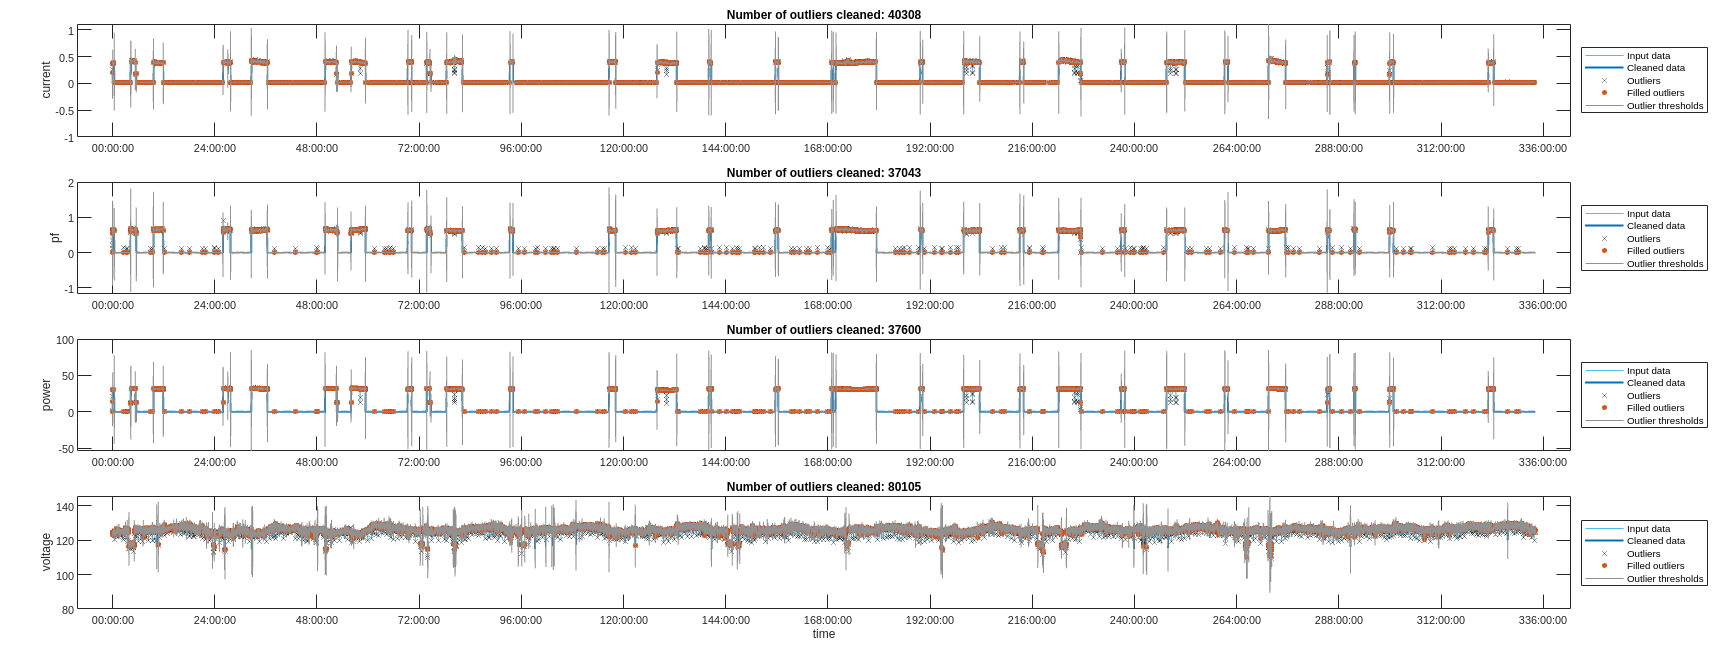


% Microwave_2
cleanedMicrowave_2= remueveOutliersInador(microwave_2,false);

% Microwave_3
cleanedMicrowave_3= remueveOutliersInador(microwave_3,false);

% Televition_1
cleanedTelevition_1= remueveOutliersInador(televition_1);


% Televition_2
cleanedTelevition_2= remueveOutliersInador(televition_2,false);

% Televition_3
cleanedTelevition_3= remueveOutliersInador(televition_3,false);


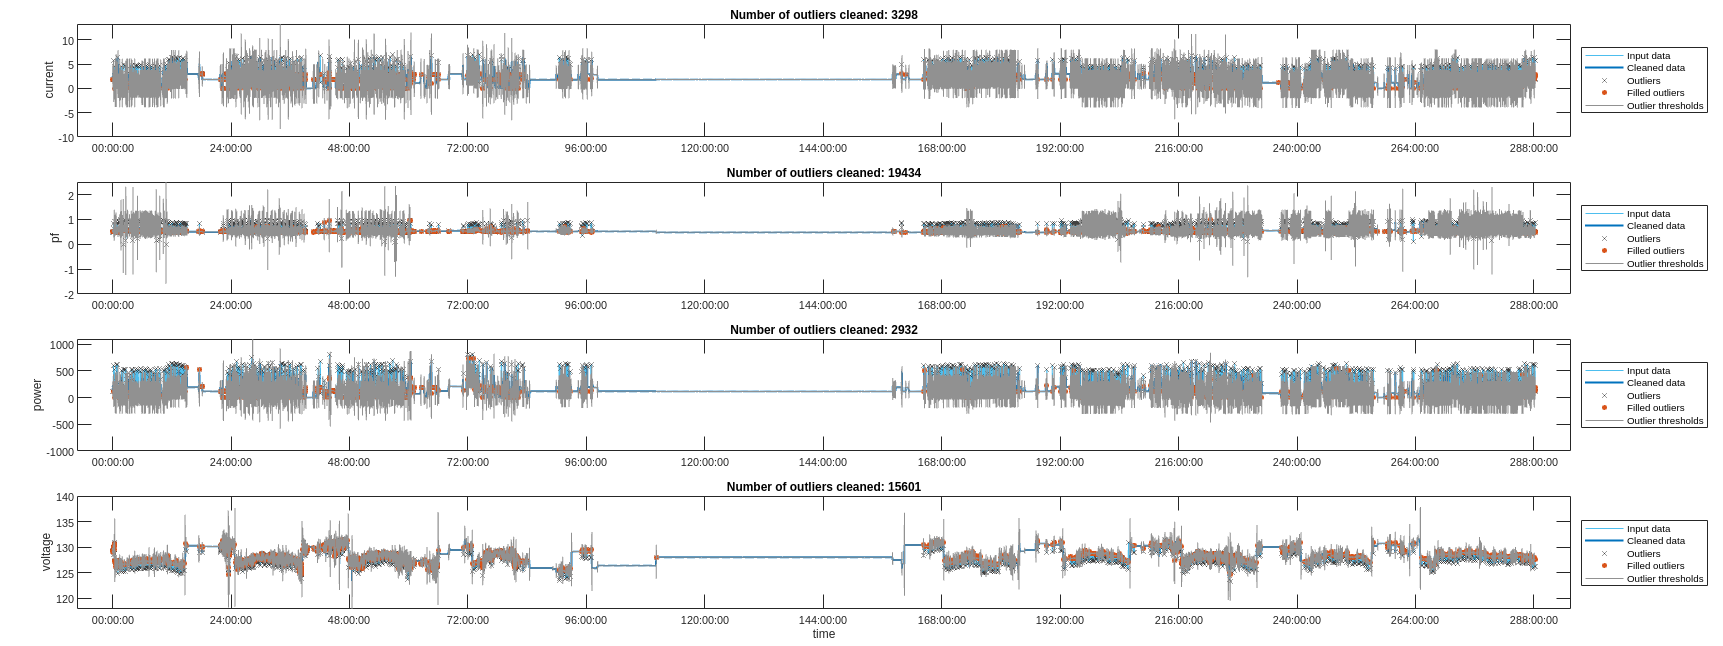

% RefrigeratorMicrowave_1
cleanedRefrigeratorMicrowave_1 = remueveOutliersInador(refrigeratorMicrowave_1);

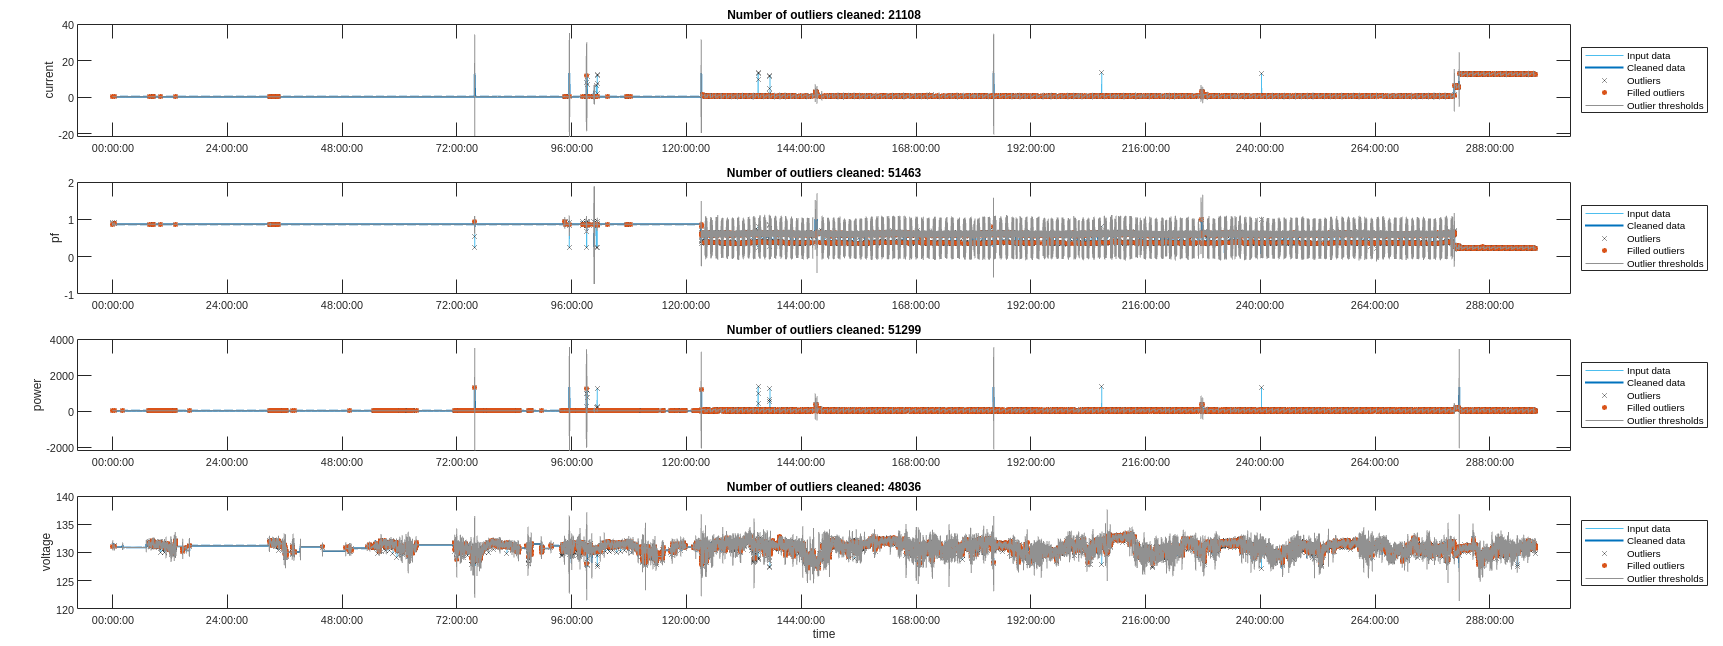


% RefrigeratorMicrowave_2
cleanedRefrigeratorMicrowave_2 = remueveOutliersInador(refrigeratorMicrowave_2);

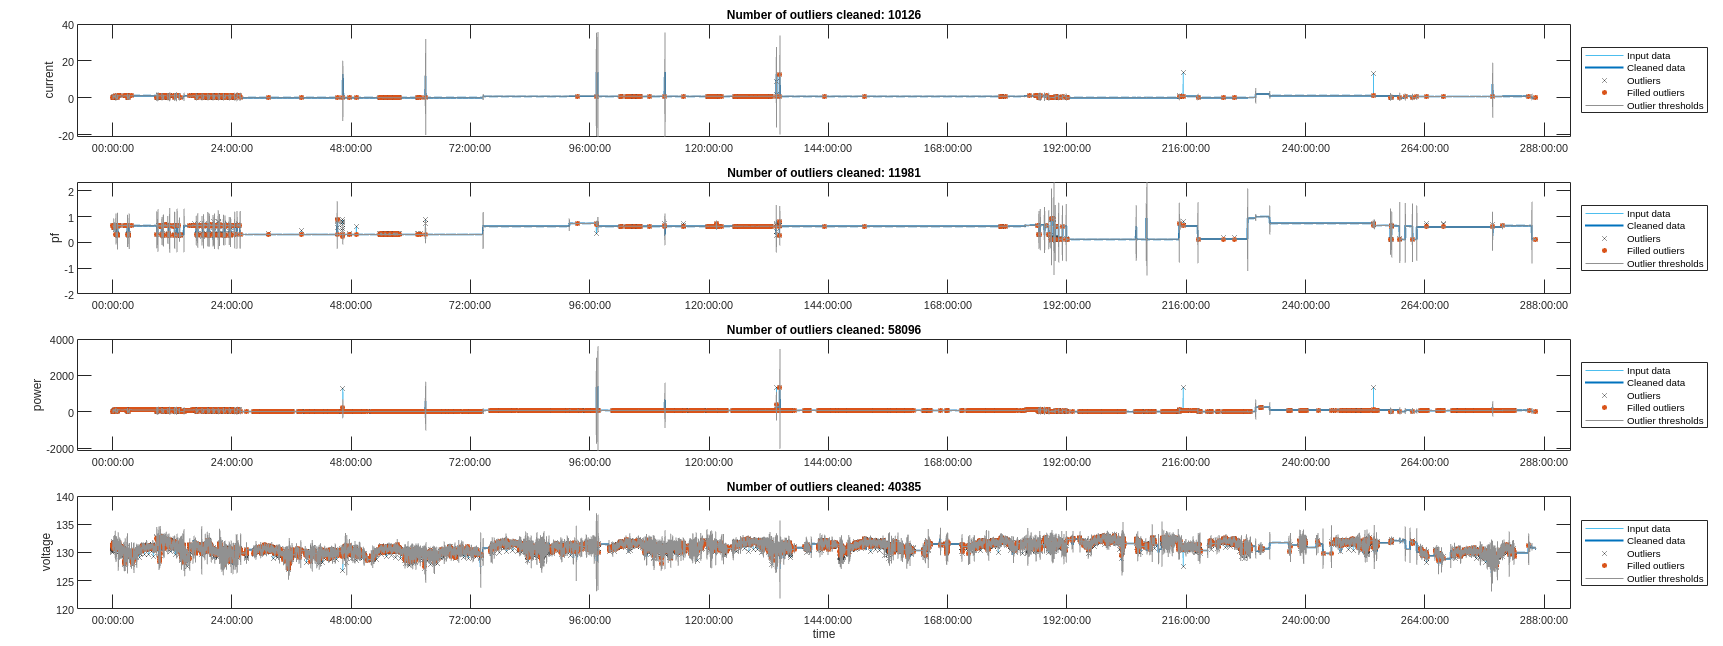


% RefrigeratorMicrowave_3
cleanedRefrigeratorMicrowave_3 = remueveOutliersInador(refrigeratorMicrowave_3);

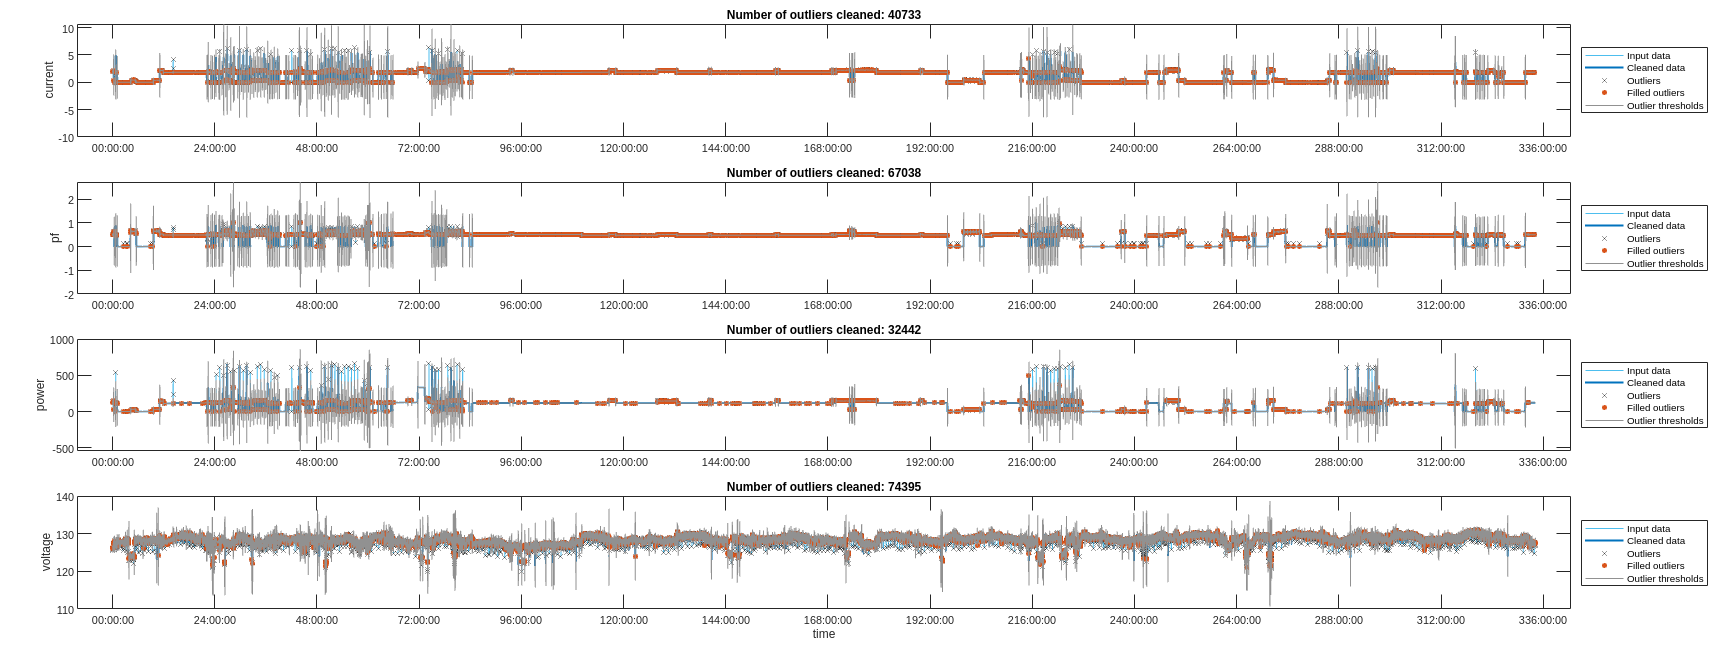

% RefrigeratorTelevision_1
% Fill outliers
cleanedRefrigeratorTelevition_1= remueveOutliersInador(refrigeratorTelevition_1);

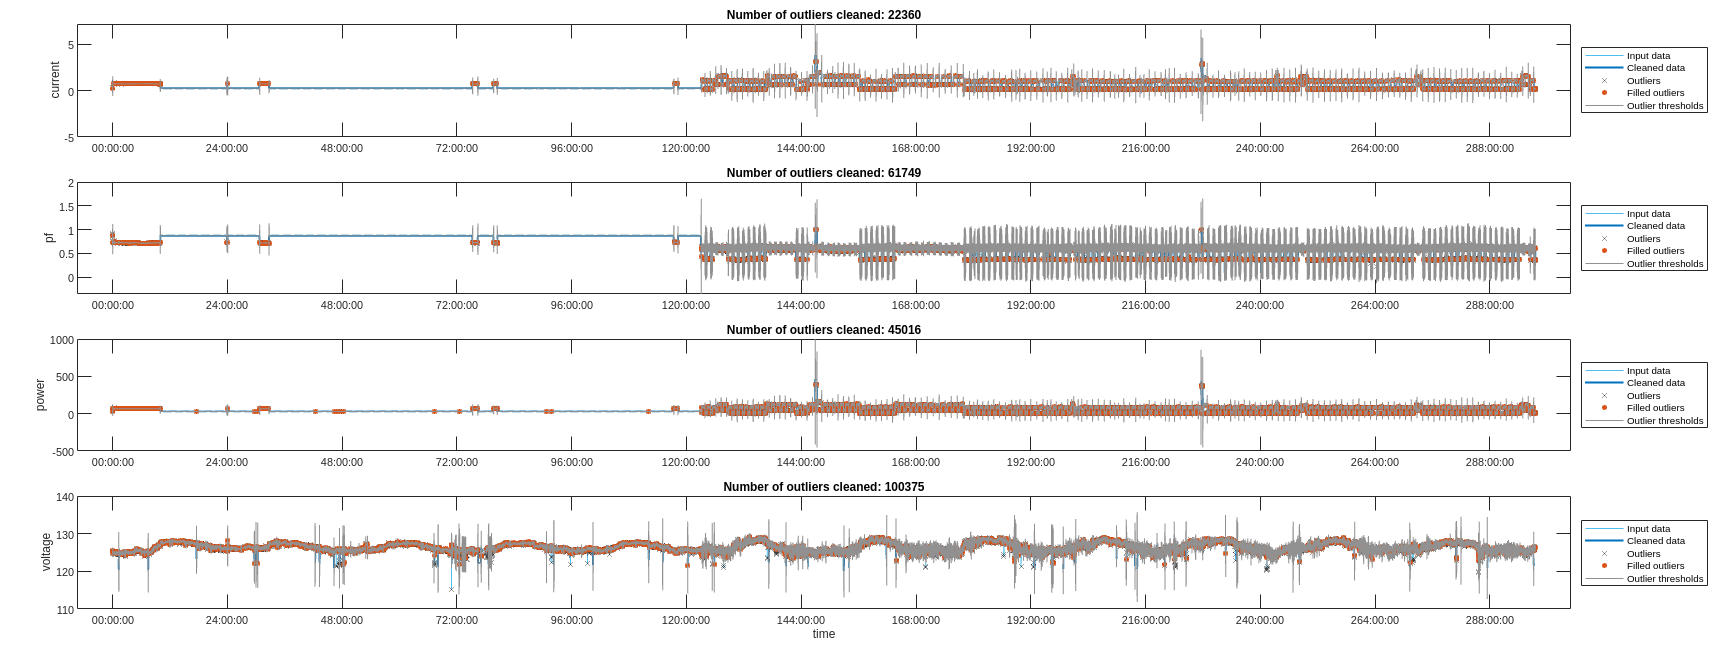


% RefrigeratorTelevision_2
% Fill outliers
cleanedRefrigeratorTelevition_2= remueveOutliersInador(refrigeratorTelevition_2);

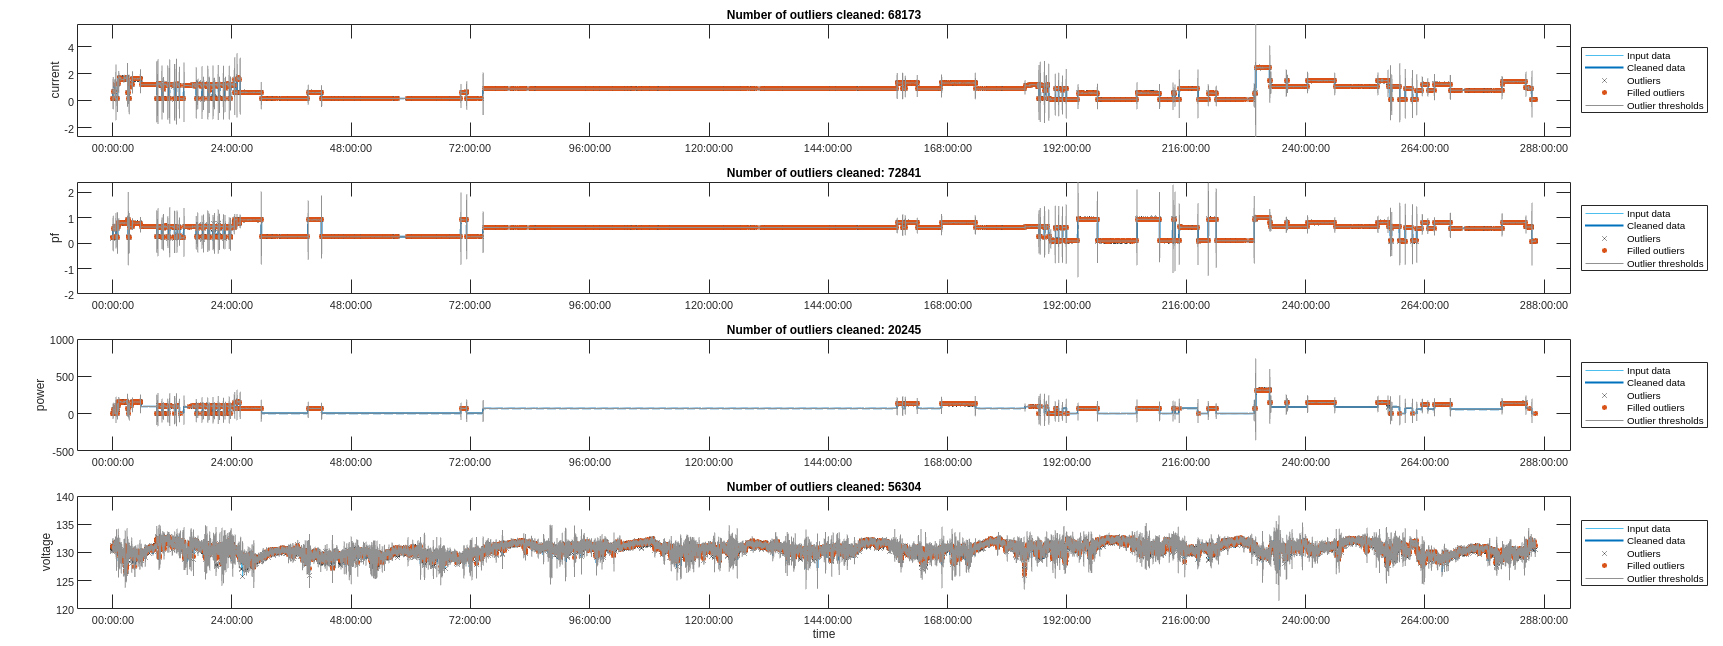


% RefrigeratorTelevision_3
% Fill outliers
cleanedRefrigeratorTelevition_3= remueveOutliersInador(refrigeratorTelevition_3);

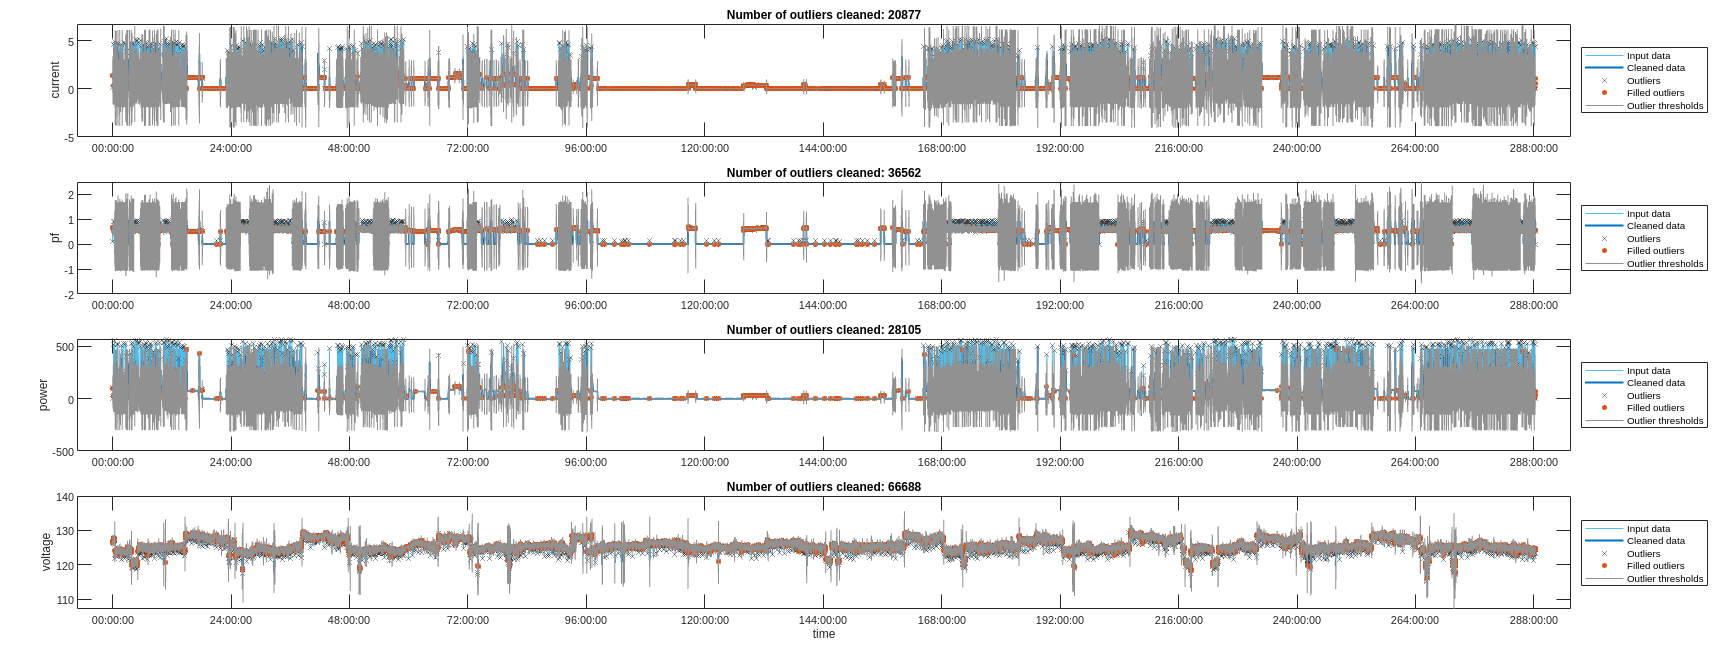

% MicrowaveTelevition_1
% Fill outliers
cleanedMicrowaveTelevition_1 = remueveOutliersInador(microwaveTelevition_1);

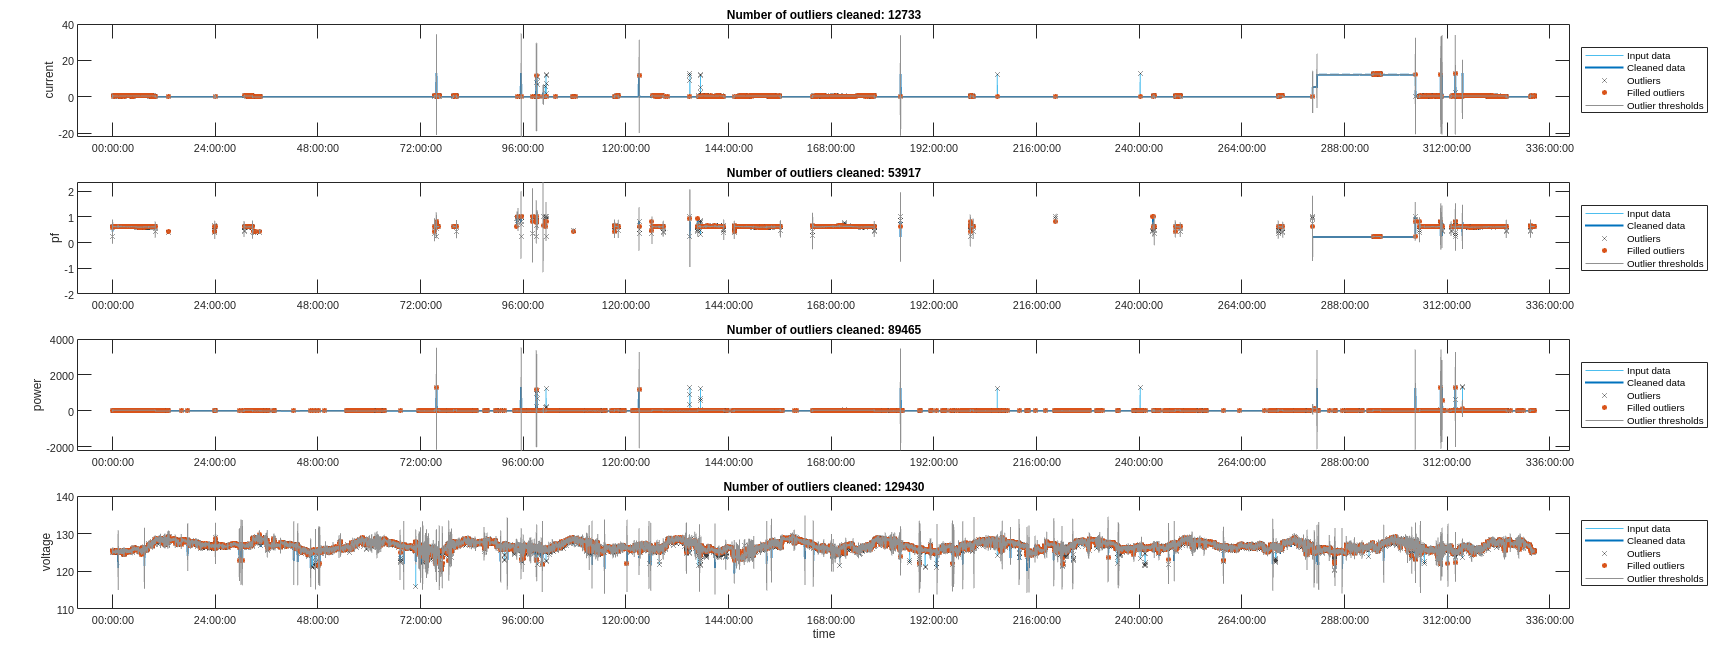


% MicrowaveTelevition_2
% Fill outliers
cleanedMicrowaveTelevition_2 = remueveOutliersInador(microwaveTelevition_2);

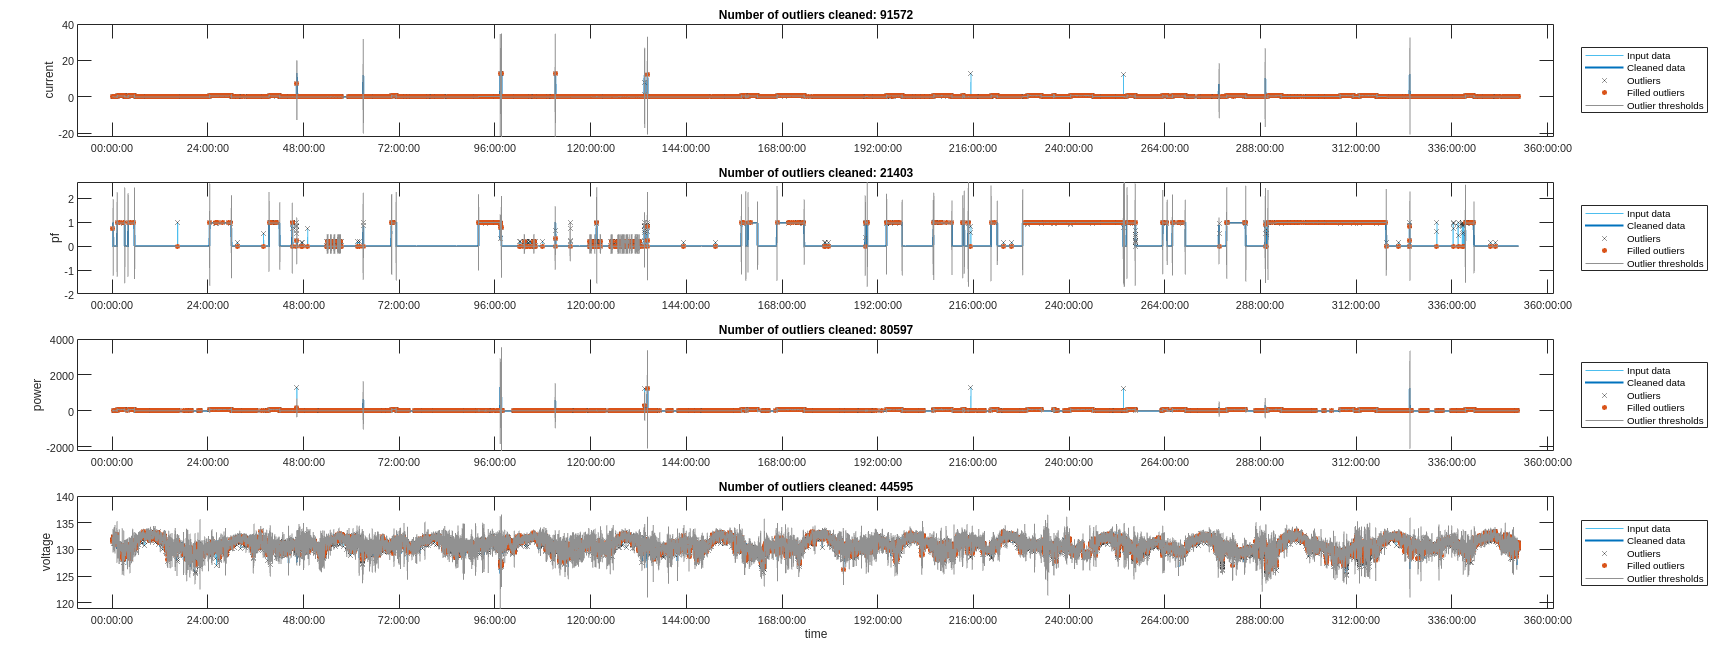


% MicrowaveTelevition_3
% Fill outliers
cleanedMicrowaveTelevition_3 = remueveOutliersInador(microwaveTelevition_3);

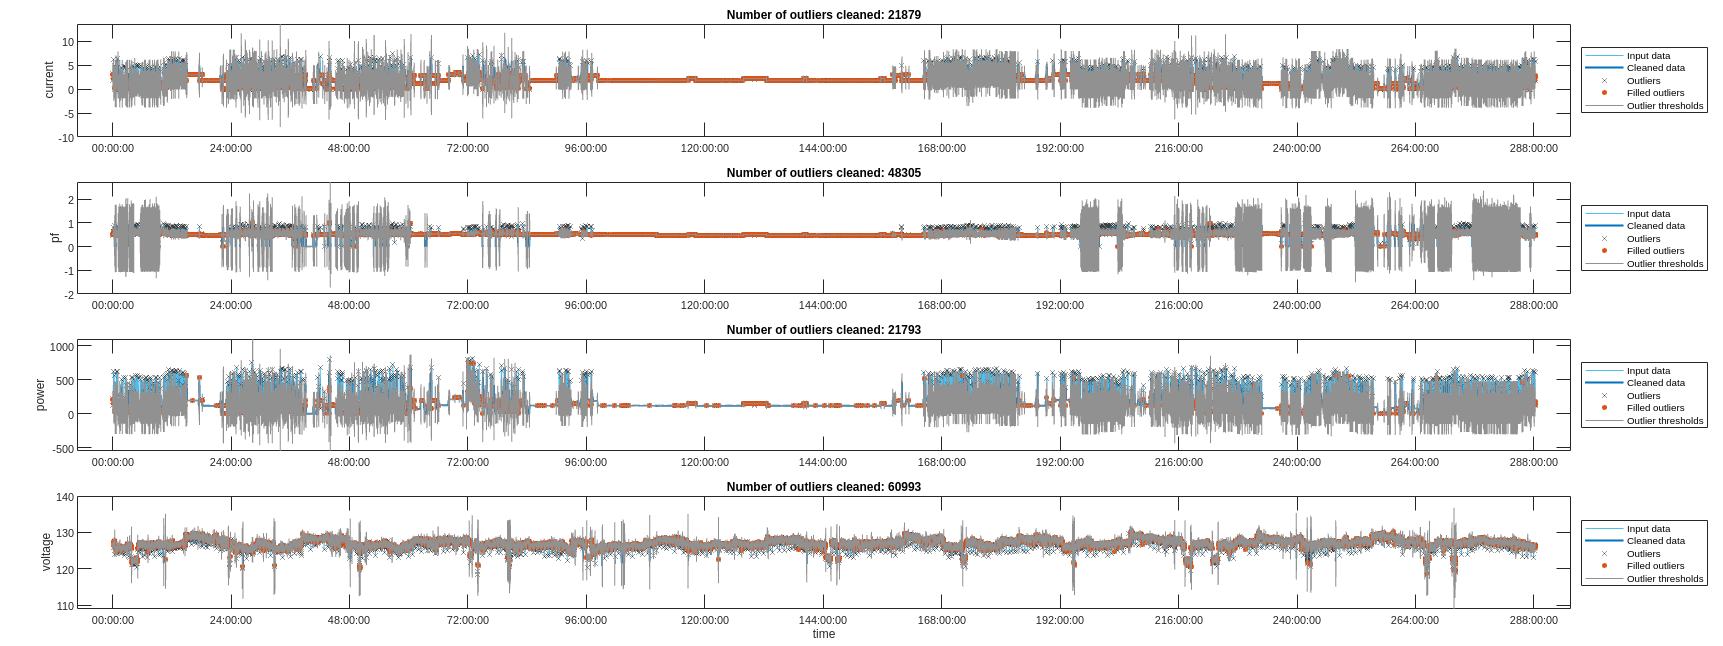

% TelevitionRefrigeratorMicrowave_1
% Fill outliers
cleanedTelevitionRefrigeratorMicrowave_1 = remueveOutliersInador(televitionRefrigeratorMicrowave_1);

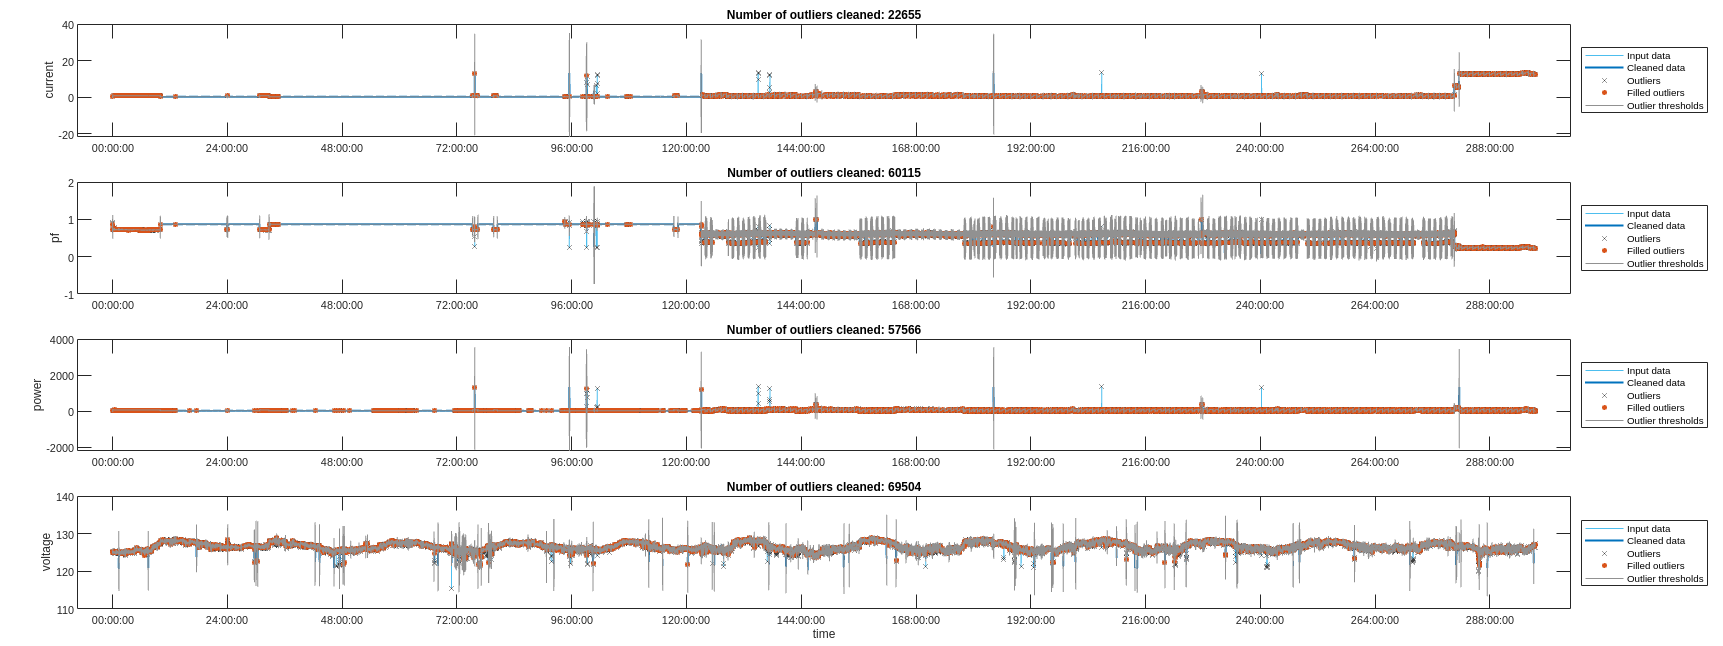


% TelevitionRefrigeratorMicrowave_2
% Fill outliers
cleanedTelevitionRefrigeratorMicrowave_2 = remueveOutliersInador(televitionRefrigeratorMicrowave_2);

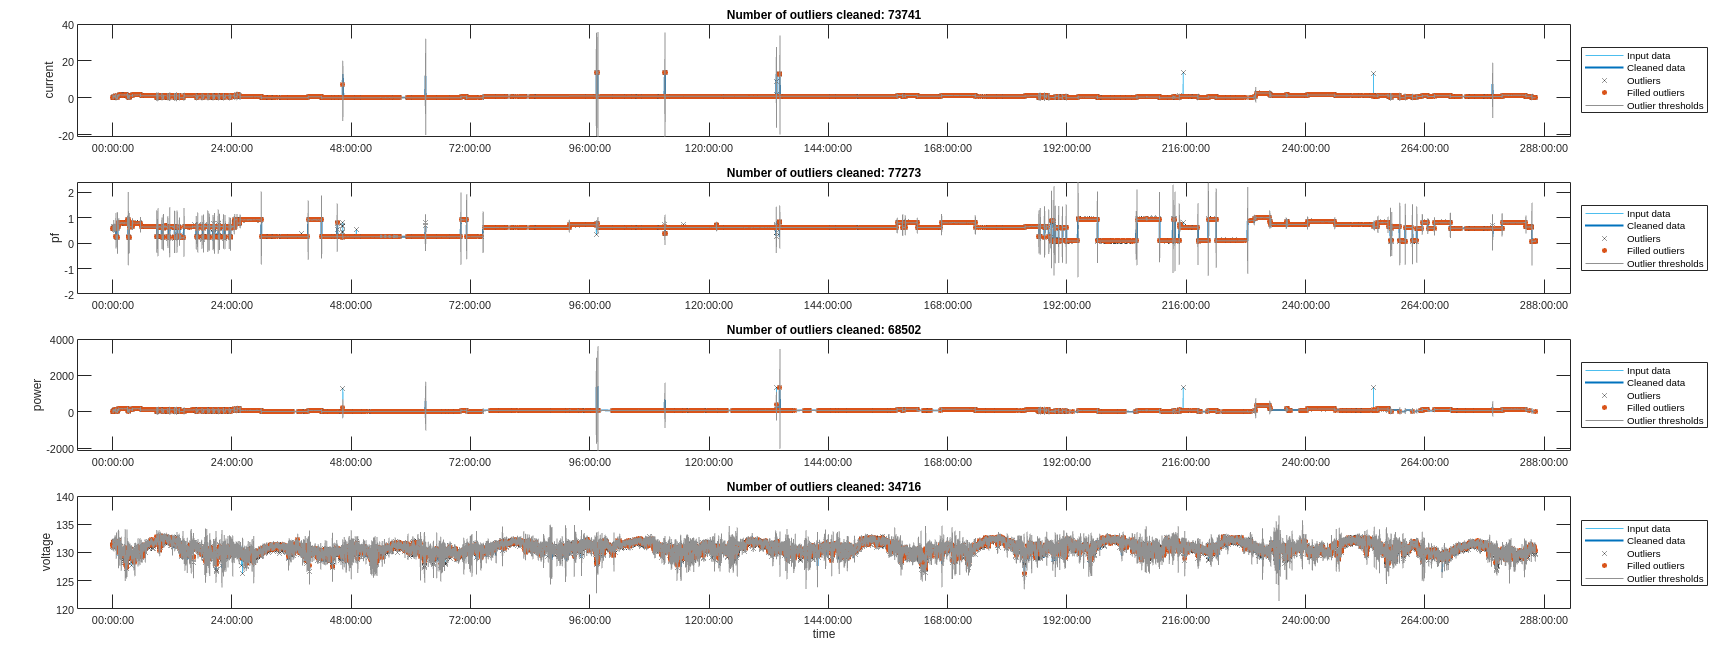


% TelevitionRefrigeratorMicrowave_3
% Fill outliers
cleanedTelevitionRefrigeratorMicrowave_3 = remueveOutliersInador(televitionRefrigeratorMicrowave_3);

## Suavizado de datos

En esta etapa, se aplicó el método de media móvil para realizar el suavizado de los datos de los refrigeradores y microondas. El objetivo principal fue reducir las variaciones bruscas y el ruido presente en las series temporales, con el fin de obtener una representación más clara del comportamiento general de cada electrodoméstico en un lapso de tiempo determinado.

Para llevar a cabo el suavizado, se utilizó una ventana de tiempo de 5 minutos para los refrigeradores y 1 minuto para los hornos de microondas. Esto implica que se calculó la media de los valores dentro de la ventana correspondiente a cada punto en el tiempo.

La elección de estas ventanas de tiempo específicas se basó en la consideración de capturar adecuadamente el trabajo de cada electrodoméstico en el lapso correspondiente. Los refrigeradores, al tener un consumo energético más estable y cambios menos rápidos, requirieron una ventana más amplia para suavizar las fluctuaciones y obtener una estimación más precisa del consumo promedio en ese período de 5 minutos. Por otro lado, los microondas, al presentar cambios más rápidos en su consumo energético, se beneficiaron de una ventana de 1 minuto para capturar con mayor fidelidad estos cambios bruscos en su funcionamiento.

El suavizado de datos mediante el método de media móvil y la aplicación de ventanas de tiempo adecuadas permitió obtener series temporales más suaves y representativas del comportamiento general de los electrodomésticos en los respectivos intervalos de tiempo considerados. Estos datos suavizados resultarán útiles para el análisis posterior y la identificación de patrones o tendencias en el consumo energético de los refrigeradores y microondas.

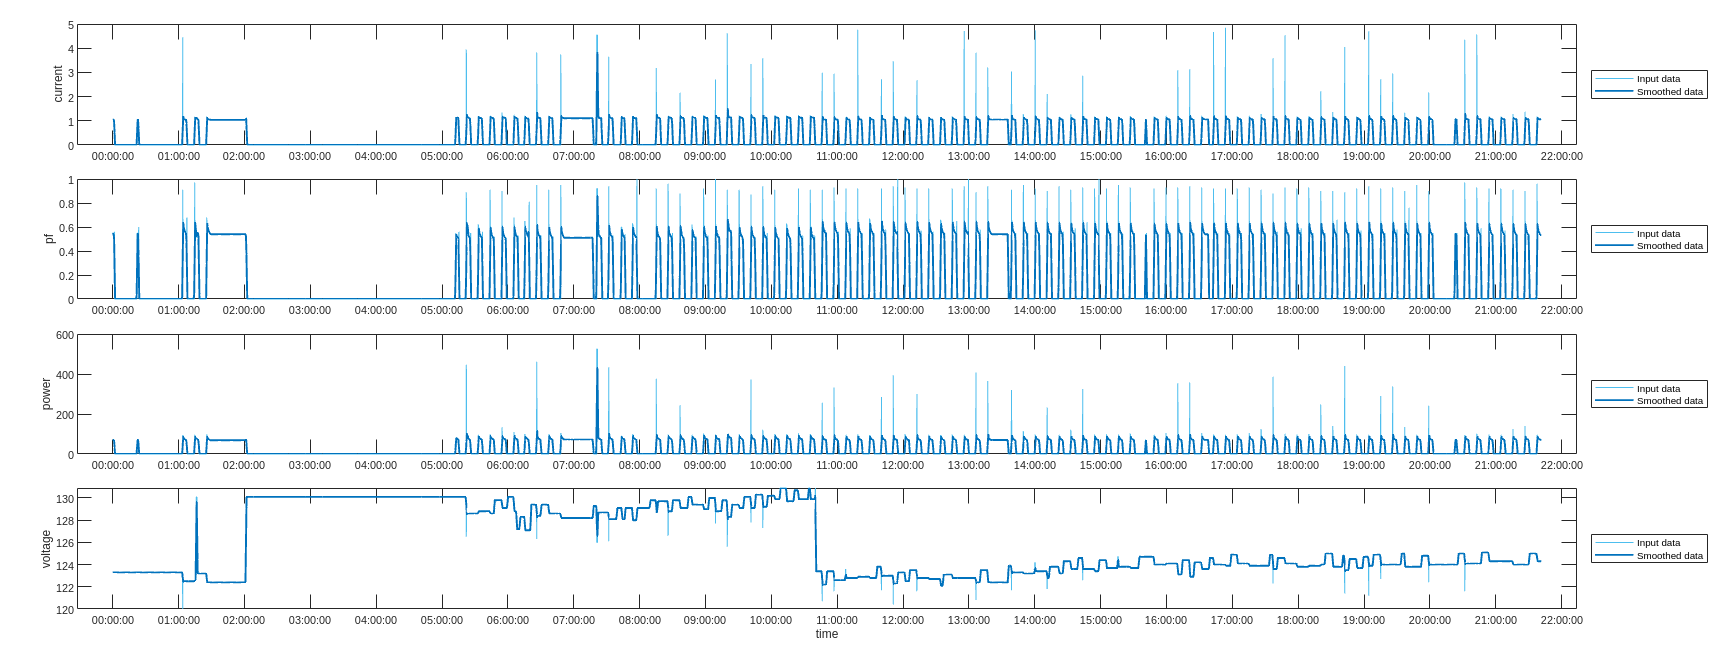

% Refrigeretor_1
smoothCleanedRefrigeretor_1 = suaveinador(cleanedRefrigerator_1);

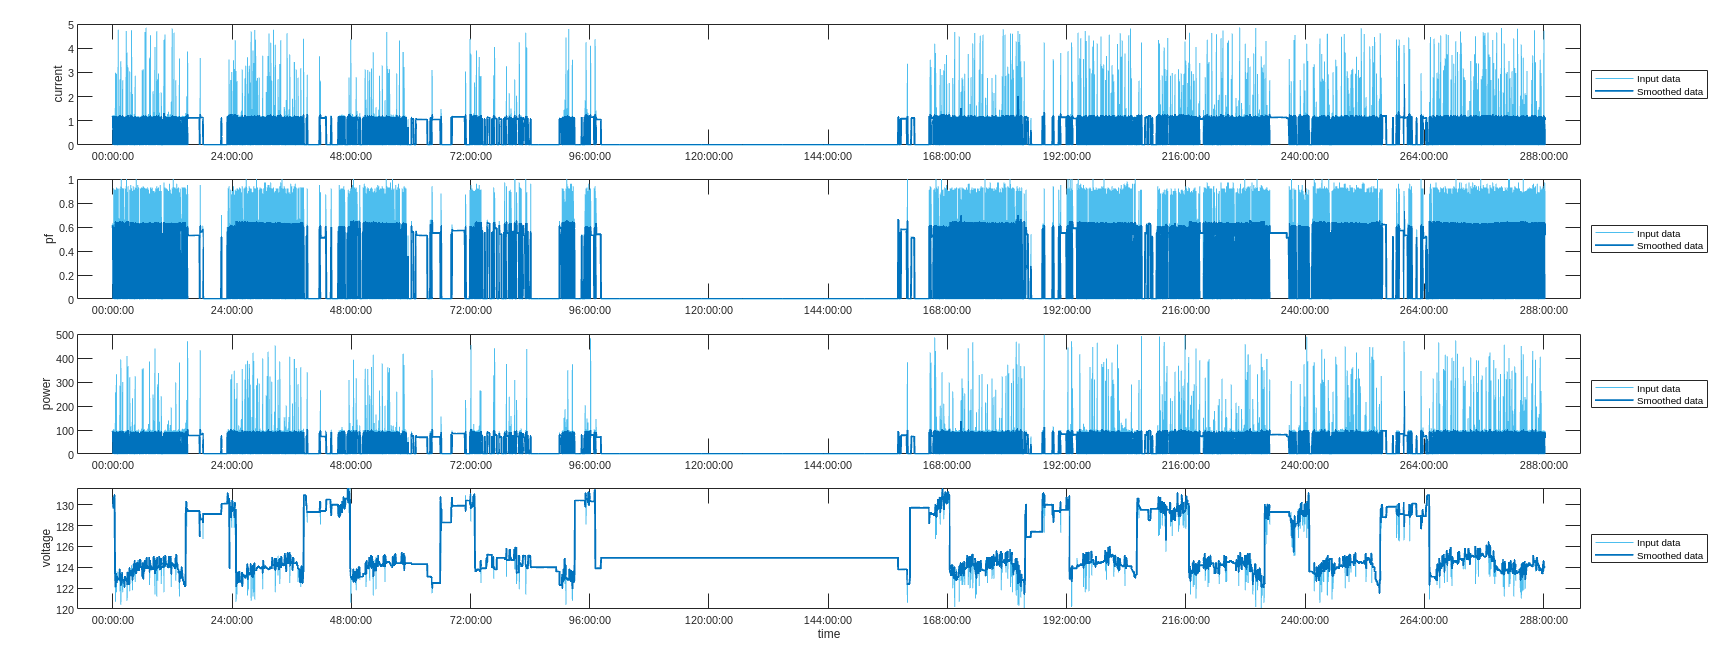


% Refrigeretor_2
% Smooth input data
smoothCleanedRefrigeretor_2 = suaveinador(cleanedRefrigerator_2,false);

% Refrigeretor_3
% Smooth input data
smoothCleanedRefrigeretor_3 = suaveinador(cleanedRefrigerator_3,false);

% Refrigeretor_4
% Smooth input data
smoothCleanedRefrigeretor_4 = suaveinador(cleanedRefrigerator_4,false);

% Microwave_1
% Smooth input data
smoothCleanedMicrowave_1 = suaveinador(cleanedMicrowave_1);

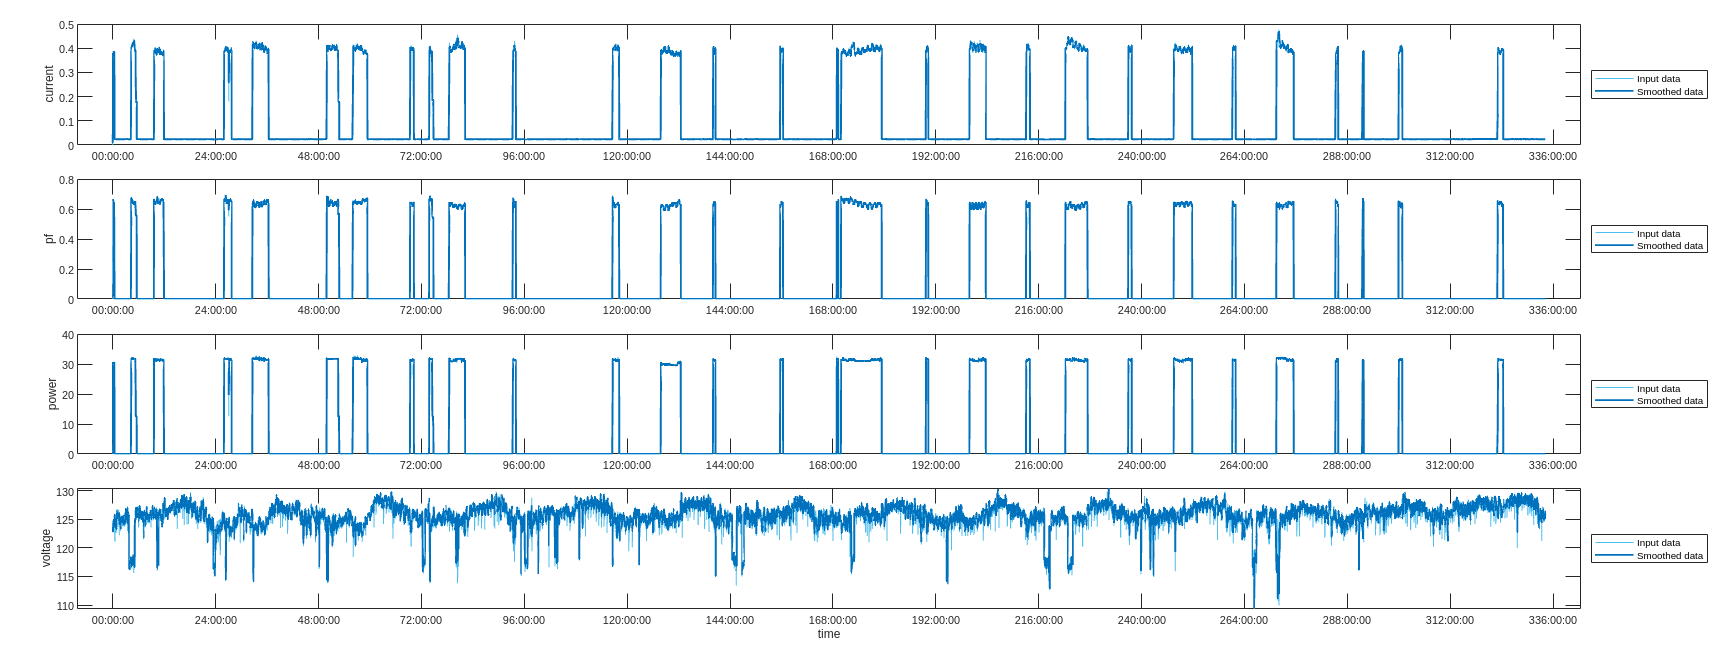


% Microwave_2
% Smooth input data
smoothCleanedMicrowave_2 = suaveinador(cleanedMicrowave_2,false);

% Microwave_3
% Smooth input data
smoothCleanedMicrowave_3 = suaveinador(cleanedMicrowave_3,false);

% Televition_1
% Smooth input data
smoothCleanedTelevition_1 = suaveinador(cleanedTelevition_1);


% Televition_2
% Smooth input data
smoothCleanedTelevition_2 = suaveinador(cleanedTelevition_2,false);

% Televition_3
% Smooth input data
smoothCleanedTelevition_3 = suaveinador(cleanedTelevition_3,false);


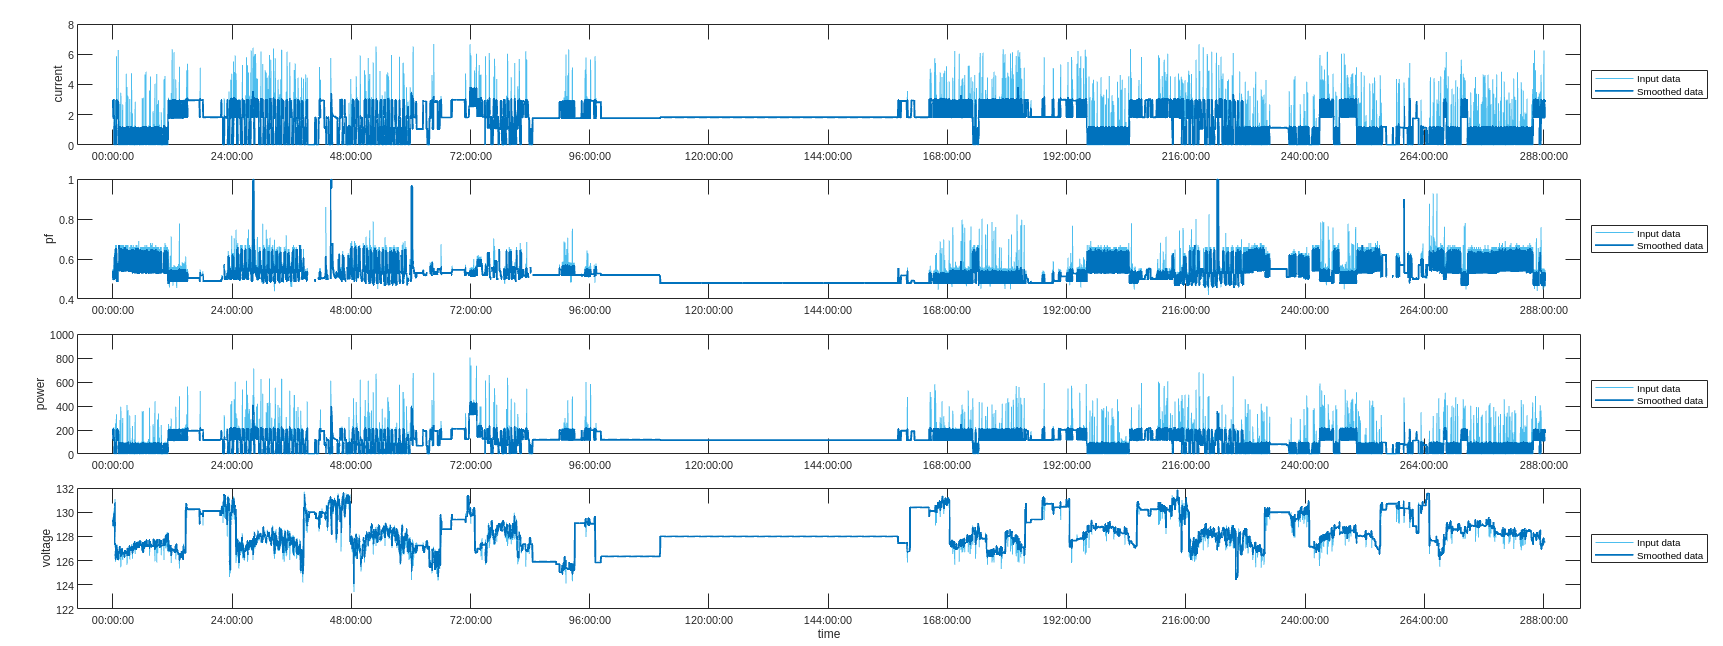

% RefrigeratorMicrowave_1
% Smooth input data
smoothCleanedRefrigeratorMicrowave_1 = suaveinador(cleanedRefrigeratorMicrowave_1);


% RefrigeratorMicrowave_2
% Smooth input data
smoothCleanedRefrigeratorMicrowave_2 = suaveinador(cleanedRefrigeratorMicrowave_2,false);

% RefrigeratorMicrowave_3
% Smooth input data
smoothCleanedRefrigeratorMicrowave_3 = suaveinador(cleanedRefrigeratorMicrowave_3,false);


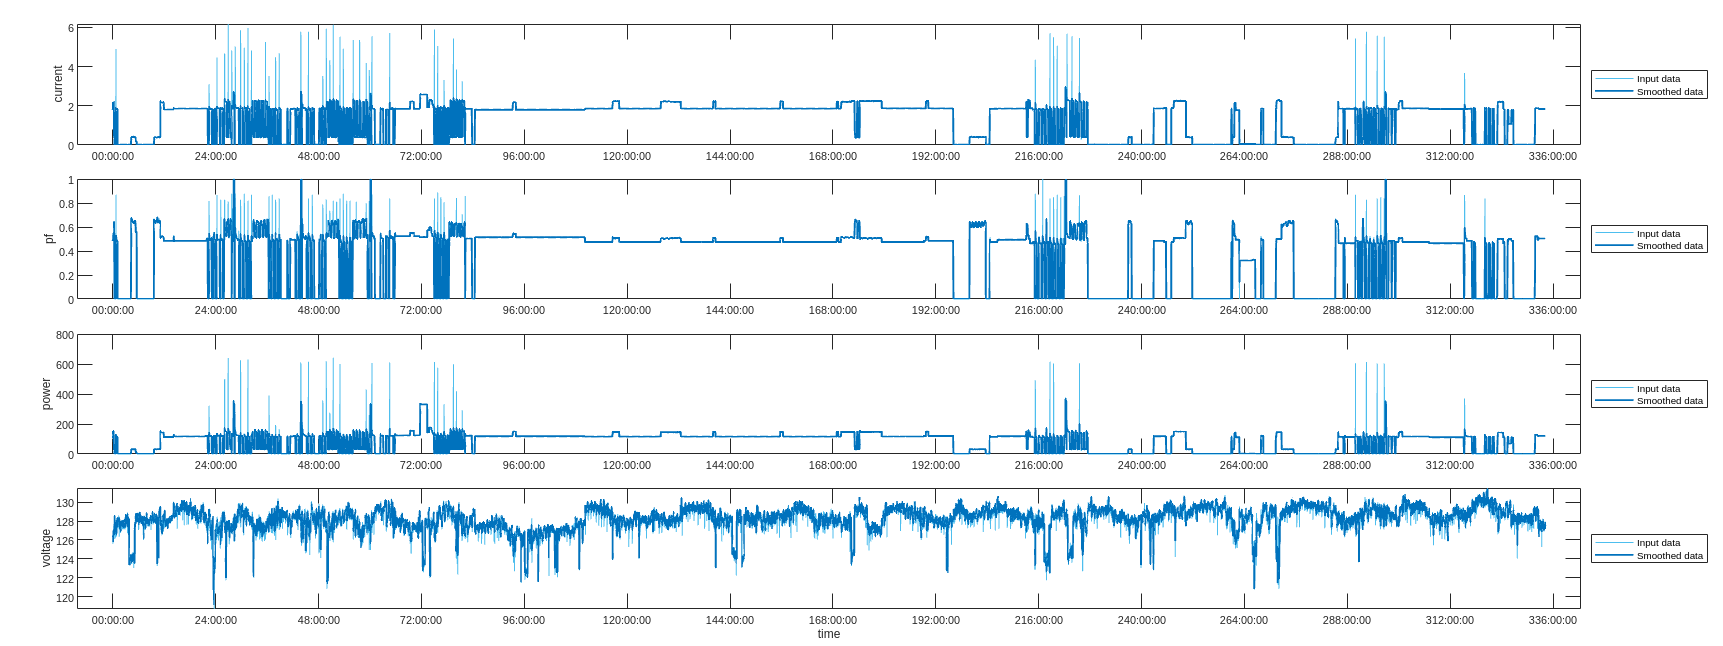

% RefrigeratorTelevition_1
% Smooth input data
smoothCleanedRefrigeratorTelevition_1 = suaveinador(cleanedRefrigeratorTelevition_1);


% RefrigeratorTelevition_2
% Smooth input data
smoothCleanedRefrigeratorTelevition_2 = suaveinador(cleanedRefrigeratorTelevition_2,false);

% RefrigeratorTelevition_3
% Smooth input data
smoothCleanedRefrigeratorTelevition_3 = suaveinador(cleanedRefrigeratorTelevition_3,false);


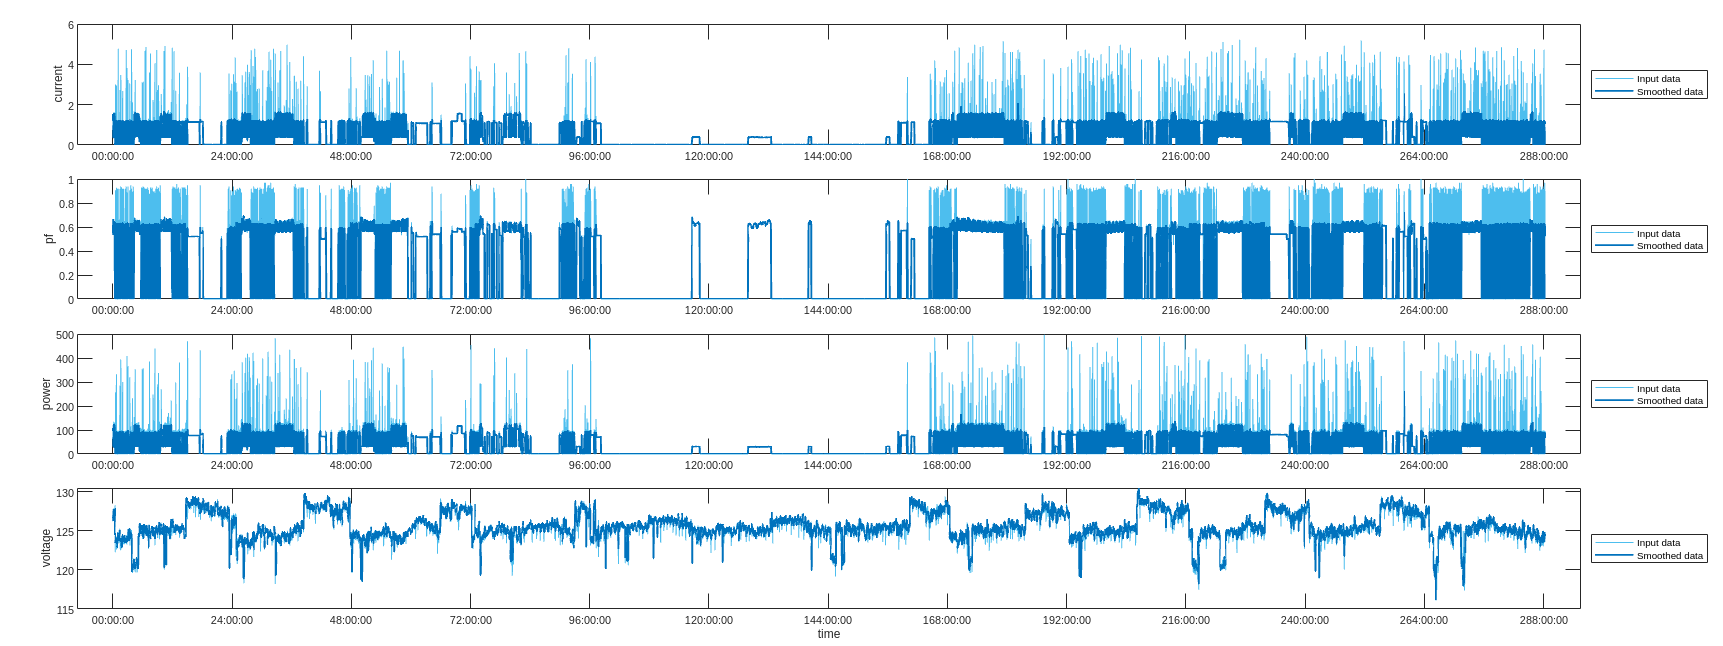

% MicrowaveTelevition_1
% Smooth input data
smoothCleanedMicrowaveTelevition_1 = suaveinador(cleanedMicrowaveTelevition_1);


% MicrowaveTelevition_2
% Smooth input data
smoothCleanedMicrowaveTelevition_2 = suaveinador(cleanedMicrowaveTelevition_2,false);

% MicrowaveTelevition_3
% Smooth input data
smoothCleanedMicrowaveTelevition_3 = suaveinador(cleanedMicrowaveTelevition_3,false);


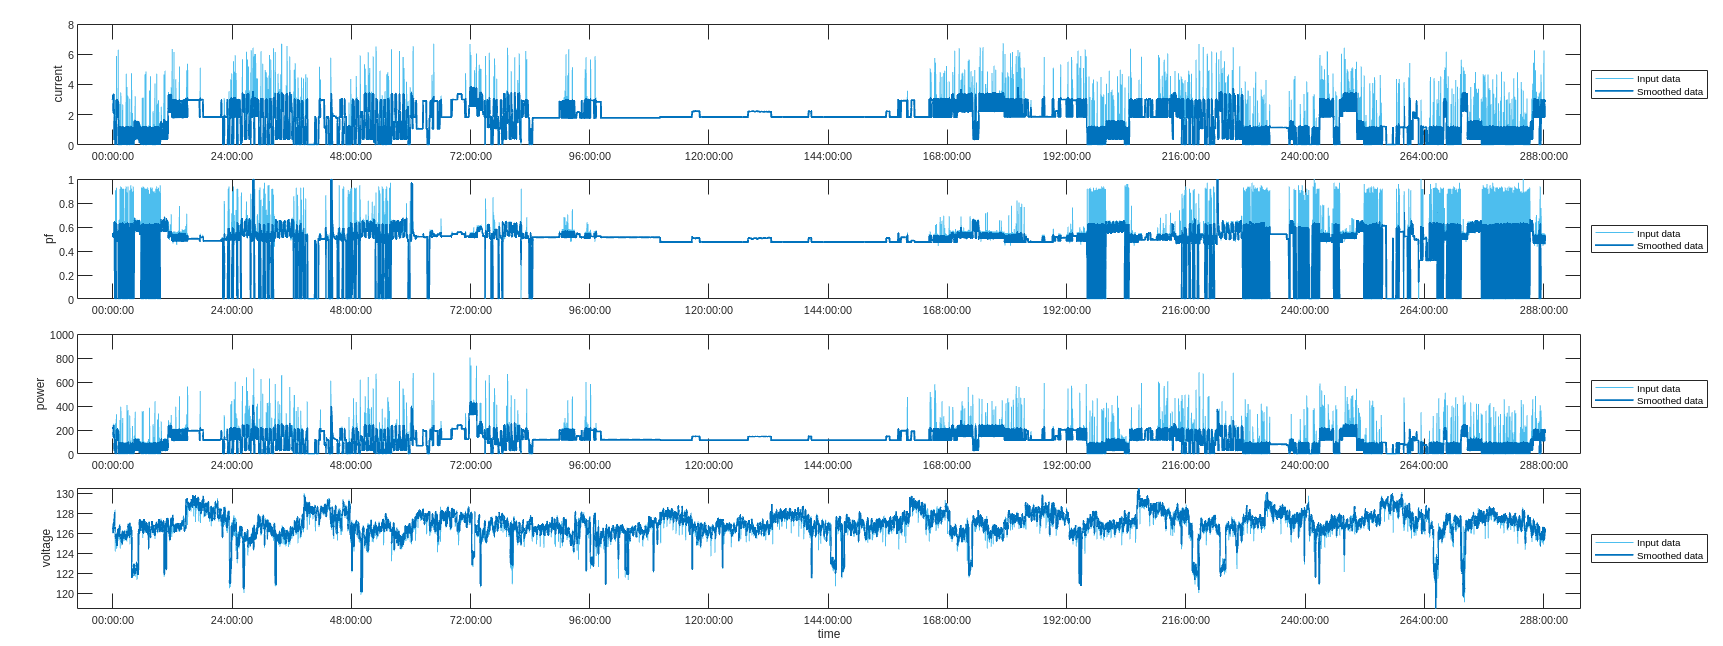

% TelevitionRefrigeratorMicrowave_1
% Smooth input data
smoothCleanedTelevitionRefrigeratorMicrowave_1 = suaveinador(cleanedTelevitionRefrigeratorMicrowave_1);


% TelevitionRefrigeratorMicrowave_2
% Smooth input data
smoothCleanedTelevitionRefrigeratorMicrowave_2 = suaveinador(cleanedTelevitionRefrigeratorMicrowave_2,false);

% TelevitionRefrigeratorMicrowave_3
% Smooth input data
smoothCleanedTelevitionRefrigeratorMicrowave_3 = suaveinador(cleanedTelevitionRefrigeratorMicrowave_3,false);


## Normalización Datos

En esta etapa, se procedió a normalizar los parámetros de corriente, potencia y voltaje utilizando el método Z-score con la desviación estándar. Es importante destacar que el factor de potencia, al ser una medida adimensional que ya se encuentra limitada a un rango de 0 a 1, no fue necesario normalizarlo mediante el método Z-score, ya que sus valores se encuentran dentro de un rango específico y no presentan la misma variabilidad que los demás parámetros.

El método Z-score es una técnica comúnmente utilizada para estandarizar variables y reducir la influencia de la escala en el análisis de datos. Consiste en calcular la desviación estándar y la media de cada parámetro y luego transformar los valores originales en desviaciones estándar con respecto a la media.

Para llevar a cabo la normalización, se realizó lo siguiente:

1. Se calculó la media y la desviación estándar de los conjuntos de datos de corriente, potencia y voltaje.

2. Se aplicó la fórmula del Z-score a cada valor de corriente, potencia y voltaje, utilizando la siguiente ecuación: 

   Z = (valor - media) / desviación estándar

Donde Z representa el valor transformado en desviaciones estándar, el valor es el dato original, la media es la media del conjunto de datos y la desviación estándar es la desviación estándar del conjunto de datos.

Al aplicar esta normalización, se logró que los valores de corriente, potencia y voltaje estén expresados en términos de su relación con la media y la variabilidad de cada parámetro. Esto facilitará el análisis comparativo y la detección de patrones o anomalías en los datos normalizados.

La normalización de los datos mediante el método Z-score contribuye a homogeneizar las escalas de los parámetros analizados, lo cual facilita su interpretación y comparación en el análisis posterior.

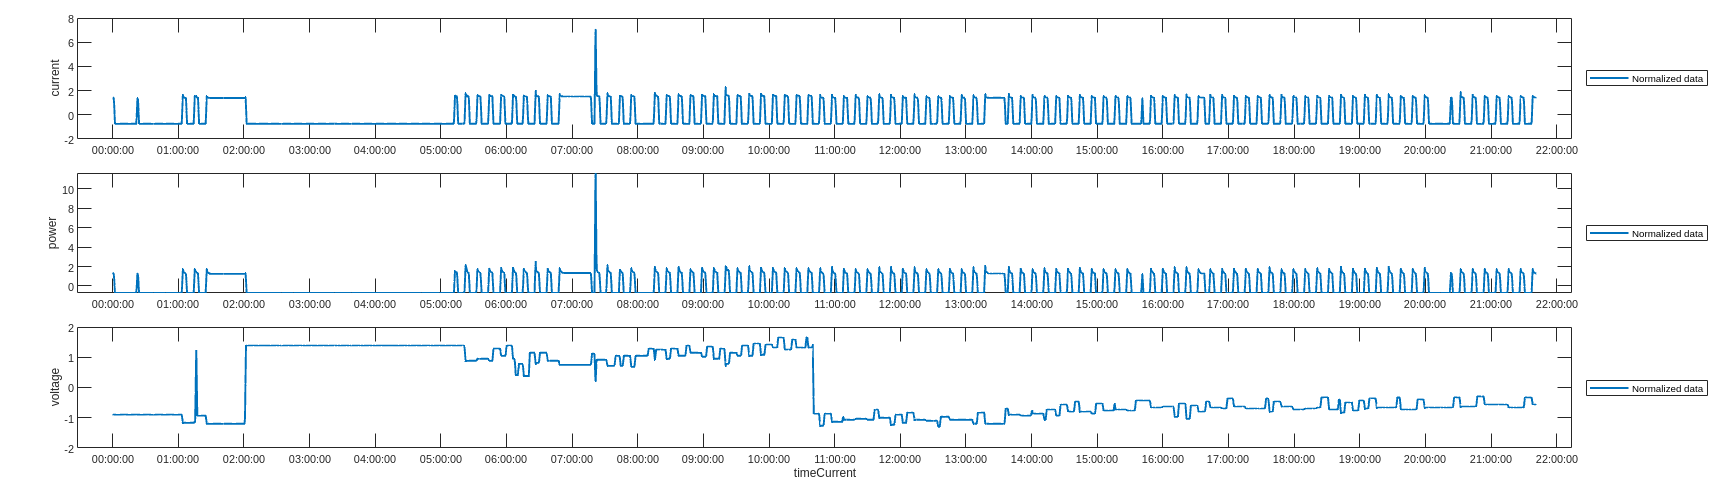

% Refrigeretor_1
normRefrigerator_1 = normalinador(smoothCleanedRefrigeretor_1);

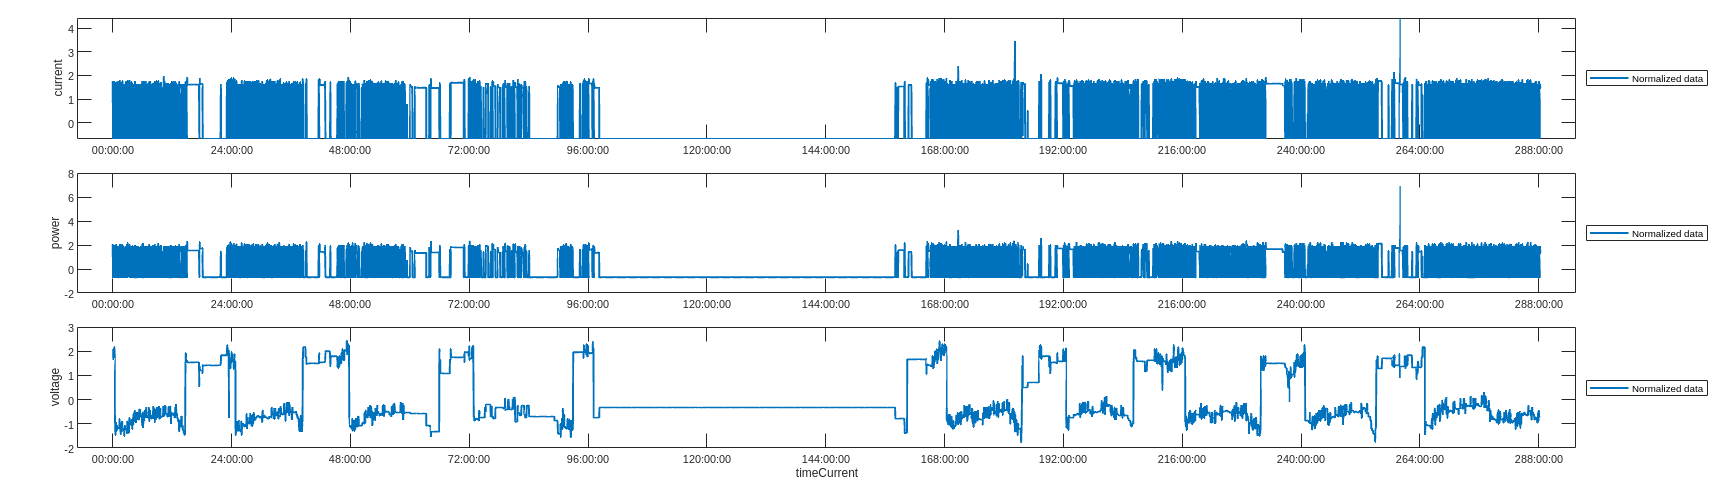


% Refrigeretor_2
normRefrigerator_2 = normalinador(smoothCleanedRefrigeretor_2,false);

% Refrigeretor_3
normRefrigerator_3 = normalinador(smoothCleanedRefrigeretor_3,false);

% Refrigeretor_4
normRefrigerator_4 = normalinador(smoothCleanedRefrigeretor_4,false);

% Microwave_1
normMicrowave_1 = normalinador(smoothCleanedMicrowave_1);

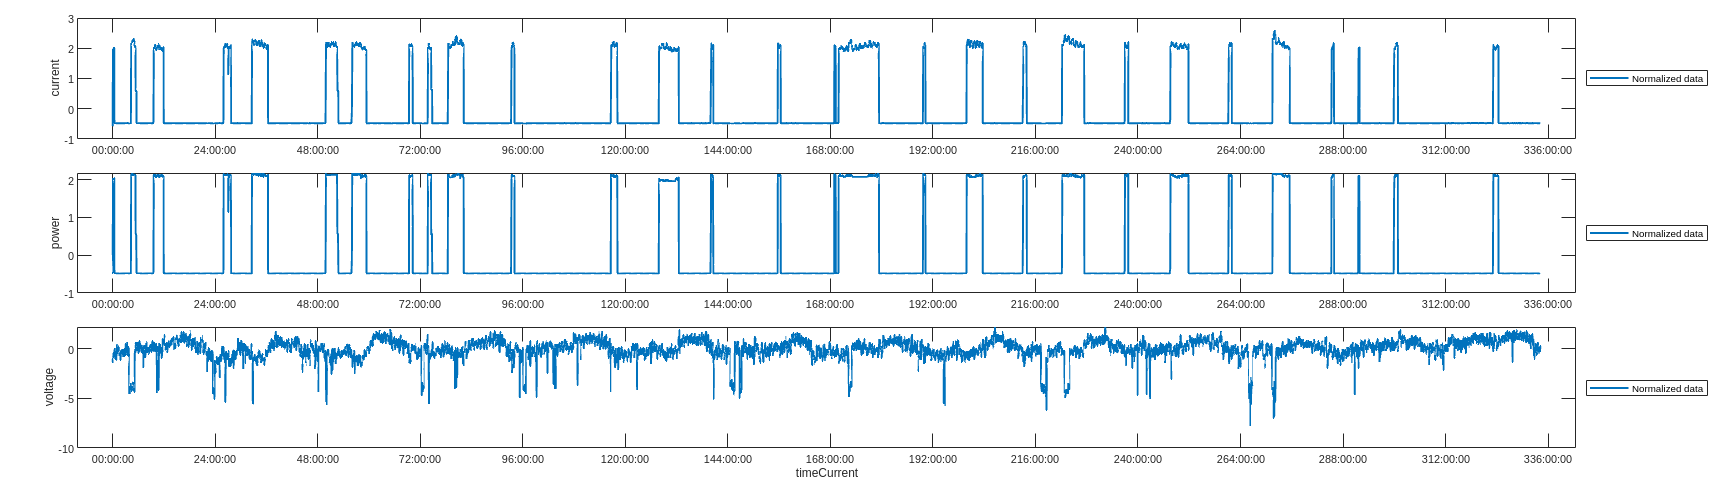


% Microwave_2
normMicrowave_2 = normalinador(smoothCleanedMicrowave_2,false);

% Microwave_3
normMicrowave_3 = normalinador(smoothCleanedMicrowave_3,false);

% Televition_1
normTelevition_1 = normalinador(smoothCleanedTelevition_1);


% Televition_2
normTelevition_2 = normalinador(smoothCleanedTelevition_2,false);

% Televition_3
normTelevition_3 = normalinador(smoothCleanedTelevition_3,false);


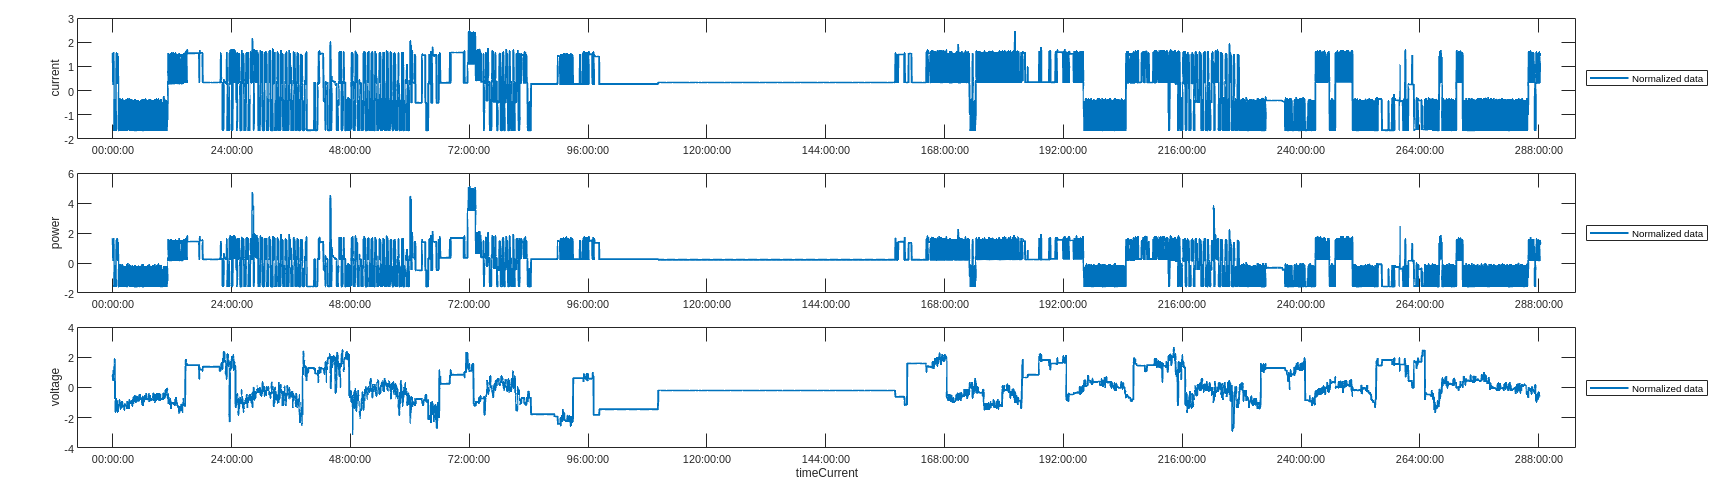

% RefrigeratorMicrowave_1
normRefrigeratorMicrowave_1 = normalinador(smoothCleanedRefrigeratorMicrowave_1);


% RefrigeratorMicrowave_2
normRefrigeratorMicrowave_2 = normalinador(smoothCleanedRefrigeratorMicrowave_2,false);

% RefrigeratorMicrowave_3
normRefrigeratorMicrowave_3 = normalinador(smoothCleanedRefrigeratorMicrowave_3,false);


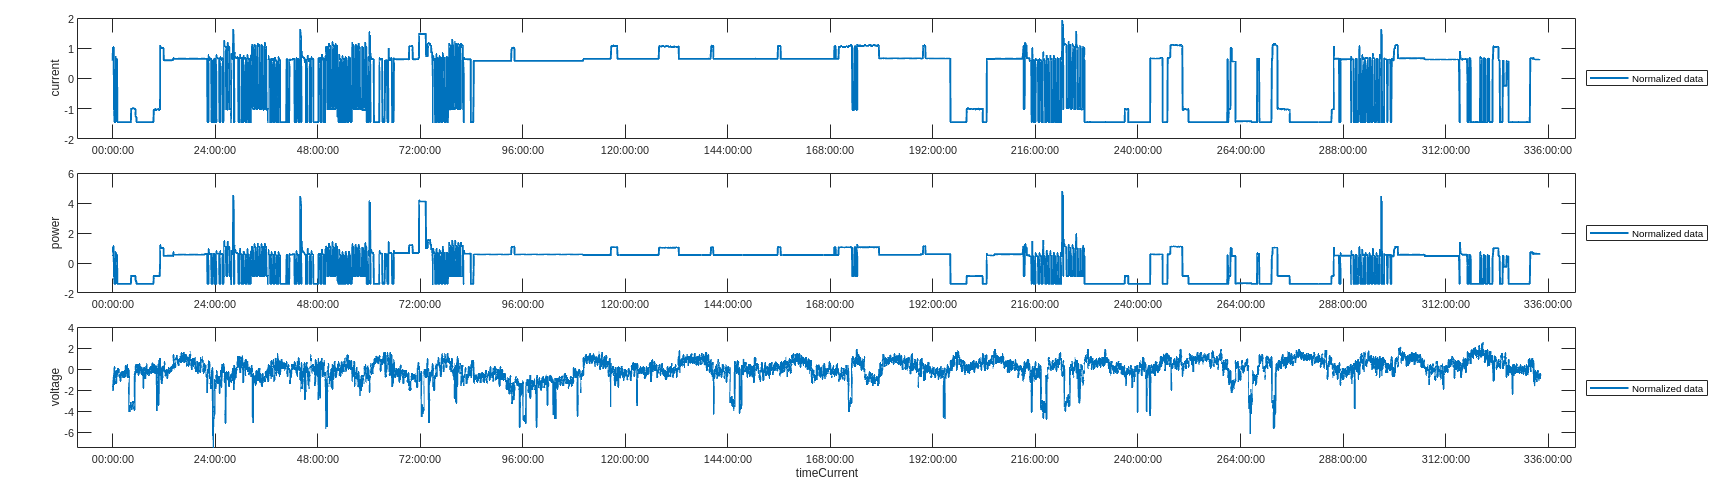

% RefrigeratorTelevition_1
normRefrigeratorTelevition_1 = normalinador(smoothCleanedRefrigeratorTelevition_1);


% RefrigeratorTelevition_2
normRefrigeratorTelevition_2 = normalinador(smoothCleanedRefrigeratorTelevition_2,false);

% RefrigeratorTelevition_3
normRefrigeratorTelevition_3 = normalinador(smoothCleanedRefrigeratorTelevition_3,false);

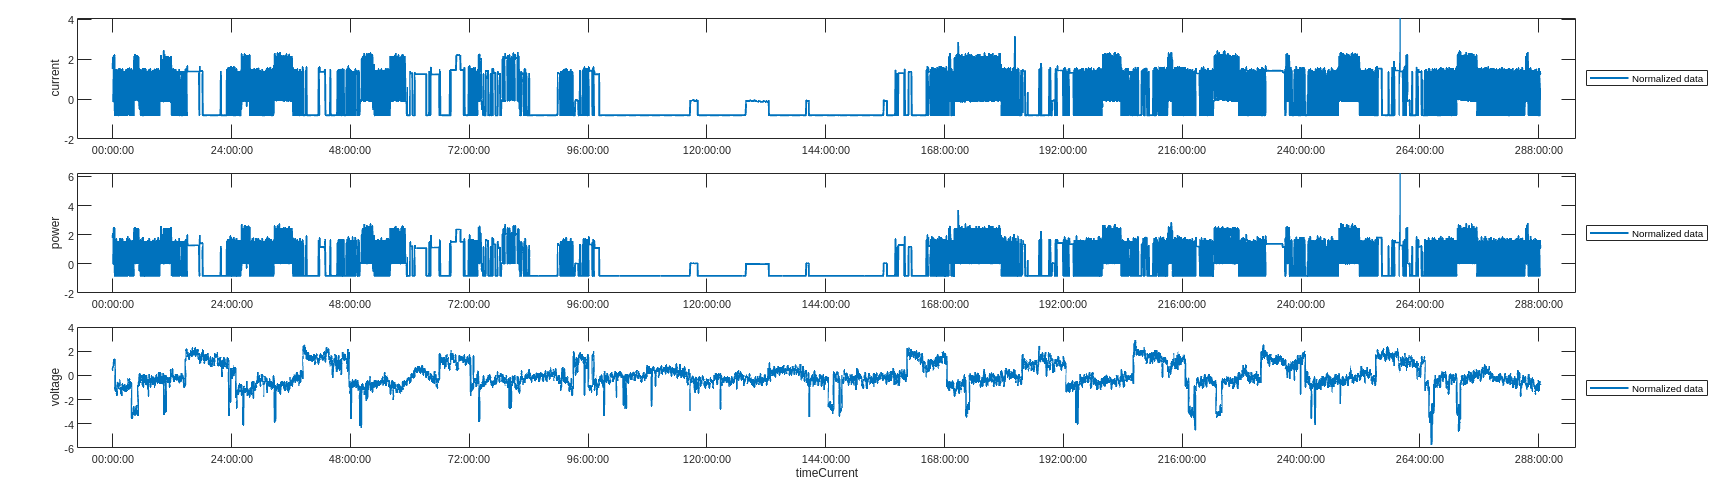

% MicrowaveTelevition_1
normMicrowaveTelevition_1 = normalinador(smoothCleanedMicrowaveTelevition_1);


% MicrowaveTelevition_2
normMicrowaveTelevition_2 = normalinador(smoothCleanedMicrowaveTelevition_2,false);

% MicrowaveTelevition_3
normMicrowaveTelevition_3 = normalinador(smoothCleanedMicrowaveTelevition_3,false);


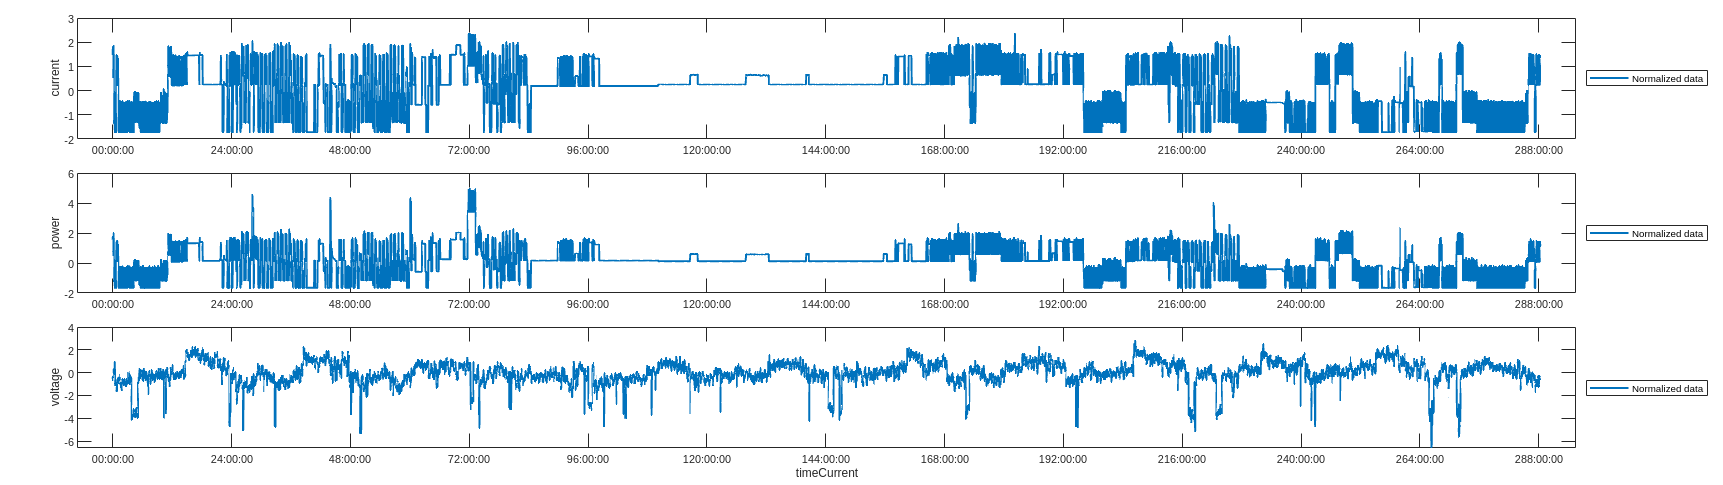

% TelevitionRefrigeratorMicrowave_1
normTelevitionRefrigeratorMicrowave_1 = normalinador(smoothCleanedTelevitionRefrigeratorMicrowave_1);


% TelevitionRefrigeratorMicrowave_2
normTelevitionRefrigeratorMicrowave_2 = normalinador(smoothCleanedTelevitionRefrigeratorMicrowave_2,false);

% TelevitionRefrigeratorMicrowave_3
normTelevitionRefrigeratorMicrowave_3 = normalinador(smoothCleanedTelevitionRefrigeratorMicrowave_3,false);

## Guardando Variables

% save('DatosLimpios_junio')

## Crando modelos clásicos

### Creando data sets

El refri 1 tiene solo 78088 por lo que lo dejaremos fuera y tomaremos 1,000,000 de datos de las demas tablas

También agregaremos una variable que sirva de etiqueta.

1.- Refrigerator.

2.- Microwave.

3.- Televition.

4.- Refrigerator, and Microwave.

5.- Refrigerator, and Televition.

6.- Microwave, and Televition.

7.- Televition, Refrigerator, and Microwave.

% Individual
normRefrigerator_2.appliances = ones(size(normRefrigerator_2.current));
normRefrigerator_3.appliances = ones(size(normRefrigerator_3.current));
normRefrigerator_4.appliances = ones(size(normRefrigerator_4.current));
normMicrowave_1.appliances = ones(size(normMicrowave_1.current))*2;
normMicrowave_2.appliances = ones(size(normMicrowave_2.current))*2;
normMicrowave_3.appliances = ones(size(normMicrowave_3.current))*2;
normTelevition_1.appliances = ones(size(normTelevition_1.current))*3;
normTelevition_2.appliances = ones(size(normTelevition_2.current))*3;
normTelevition_3.appliances = ones(size(normTelevition_3.current))*3;

% Refrigerator and Microwave
normRefrigeratorMicrowave_1.appliances = ones(size(normRefrigeratorMicrowave_1.current))*4;
normRefrigeratorMicrowave_2.appliances = ones(size(normRefrigeratorMicrowave_2.current))*4;
normRefrigeratorMicrowave_3.appliances = ones(size(normRefrigeratorMicrowave_3.current))*4;

% Refrigerator and Televition
normRefrigeratorTelevition_1.appliances = ones(size(normRefrigeratorTelevition_1.current))*5;
normRefrigeratorTelevition_2.appliances = ones(size(normRefrigeratorTelevition_2.current))*5;
normRefrigeratorTelevition_3.appliances = ones(size(normRefrigeratorTelevition_3.current))*5;

% Microwave and Televition
normMicrowaveTelevition_1.appliances = ones(size(normMicrowaveTelevition_1.current))*6;
normMicrowaveTelevition_2.appliances = ones(size(normMicrowaveTelevition_2.current))*6;
normMicrowaveTelevition_3.appliances = ones(size(normMicrowaveTelevition_3.current))*6;

% Televition, Refrigerator and Microwave
normTelevitionRefrigeratorMicrowave_1.appliances = ones(size(normTelevitionRefrigeratorMicrowave_1.current))*7;
normTelevitionRefrigeratorMicrowave_2.appliances = ones(size(normTelevitionRefrigeratorMicrowave_2.current))*7;
normTelevitionRefrigeratorMicrowave_3.appliances = ones(size(normTelevitionRefrigeratorMicrowave_3.current))*7;

Formamos Dataset, usaremos Cell, y dentro de cada Cell se guardaran los chunks, si sizeChunk=100 y tenemos 1,000 muestras en una tabla, tendremos solo 10 filas en dataCell, cada fila debe guardar un chunk y su respectiva categoria

sample_size = 60;

[normMicrowave_1Array, normMicrowave_1Labels] = TimeTable2SequenceArray(normMicrowave_1, sample_size);
[normMicrowave_2Array, normMicrowave_2Labels] = TimeTable2SequenceArray(normMicrowave_2, sample_size);
[normMicrowave_3Array, normMicrowave_3Labels] = TimeTable2SequenceArray(normMicrowave_3, sample_size);

[normRefrigerator_2Array, normRefrigerator_2Labels] = TimeTable2SequenceArray(normRefrigerator_2, sample_size);
[normRefrigerator_3Array, normRefrigerator_3Labels] = TimeTable2SequenceArray(normRefrigerator_3, sample_size);
[normRefrigerator_4Array, normRefrigerator_4Labels] = TimeTable2SequenceArray(normRefrigerator_4, sample_size);

[normTelevition_1Array, normTelevition_1Labels] = TimeTable2SequenceArray(normTelevition_1, sample_size);
[normTelevition_2Array, normTelevition_2Labels] = TimeTable2SequenceArray(normTelevition_2, sample_size);
[normTelevition_3Array, normTelevition_3Labels] = TimeTable2SequenceArray(normTelevition_3, sample_size);

[normRefrigeratorMicrowave_1Array, normRefrigeratorMicrowave_1Labels] = TimeTable2SequenceArray(normRefrigeratorMicrowave_1, sample_size);
[normRefrigeratorMicrowave_2Array, normRefrigeratorMicrowave_2Labels] = TimeTable2SequenceArray(normRefrigeratorMicrowave_2, sample_size);
[normRefrigeratorMicrowave_3Array, normRefrigeratorMicrowave_3Labels] = TimeTable2SequenceArray(normRefrigeratorMicrowave_3, sample_size);

[normRefrigeratorTelevition_1Array, normRefrigeratorTelevition_1Labels] = TimeTable2SequenceArray(normRefrigeratorTelevition_1, sample_size);
[normRefrigeratorTelevition_2Array, normRefrigeratorTelevition_2Labels] = TimeTable2SequenceArray(normRefrigeratorTelevition_2, sample_size);
[normRefrigeratorTelevition_3Array, normRefrigeratorTelevition_3Labels] = TimeTable2SequenceArray(normRefrigeratorTelevition_3, sample_size);

[normMicrowaveTelevition_1Array, normMicrowaveTelevition_1Labels] = TimeTable2SequenceArray(normMicrowaveTelevition_1, sample_size);
[normMicrowaveTelevition_2Array, normMicrowaveTelevition_2Labels] = TimeTable2SequenceArray(normMicrowaveTelevition_2, sample_size);
[normMicrowaveTelevition_3Array, normMicrowaveTelevition_3Labels] = TimeTable2SequenceArray(normMicrowaveTelevition_3, sample_size);

[normTelevitionRefrigeratorMicrowave_1Array, normTelevitionRefrigeratorMicrowave_1Labels] = TimeTable2SequenceArray(normTelevitionRefrigeratorMicrowave_1, sample_size);
[normTelevitionRefrigeratorMicrowave_2Array, normTelevitionRefrigeratorMicrowave_2Labels] = TimeTable2SequenceArray(normTelevitionRefrigeratorMicrowave_2, sample_size);
[normTelevitionRefrigeratorMicrowave_3Array, normTelevitionRefrigeratorMicrowave_3Labels] = TimeTable2SequenceArray(normTelevitionRefrigeratorMicrowave_3, sample_size);

datasetArray = [normMicrowave_1Array; normMicrowave_2Array; normMicrowave_3Array; normRefrigerator_2Array; normRefrigerator_3Array; normRefrigerator_4Array; ...
    normTelevition_1Array; normTelevition_2Array; normTelevition_3Array; normRefrigeratorMicrowave_1Array; normRefrigeratorMicrowave_2Array; normRefrigeratorMicrowave_3Array; ...
    normRefrigeratorTelevition_1Array; normRefrigeratorTelevition_2Array; normRefrigeratorTelevition_3Array; normMicrowaveTelevition_1Array; normMicrowaveTelevition_2Array; ...
    normMicrowaveTelevition_3Array; normTelevitionRefrigeratorMicrowave_1Array; normTelevitionRefrigeratorMicrowave_2Array; normTelevitionRefrigeratorMicrowave_3Array];

datasetLabels = [normMicrowave_1Labels; normMicrowave_2Labels; normMicrowave_3Labels; normRefrigerator_2Labels; normRefrigerator_3Labels; normRefrigerator_4Labels; ...
    normTelevition_1Labels; normTelevition_2Labels; normTelevition_3Labels; normRefrigeratorMicrowave_1Labels; normRefrigeratorMicrowave_2Labels; normRefrigeratorMicrowave_3Labels; ...
    normRefrigeratorTelevition_1Labels; normRefrigeratorTelevition_2Labels; normRefrigeratorTelevition_3Labels; normMicrowaveTelevition_1Labels; normMicrowaveTelevition_2Labels; ...
    normMicrowaveTelevition_3Labels; normTelevitionRefrigeratorMicrowave_1Labels; normTelevitionRefrigeratorMicrowave_2Labels; normTelevitionRefrigeratorMicrowave_3Labels];

save dataCurrent60seconds.mat datasetArray datasetLabels

### Datos de entrenamiento

dataPartitions1 = cvpartition(dataSet1.appliances,"HoldOut",0.4);
trainDataSet1 = dataSet1(training(dataPartitions1),2:end);    
testDataSet1 = dataSet1(test(dataPartitions1),2:end);

dataPartitions2 = cvpartition(dataSet2.appliances,"HoldOut",0.4);
trainDataSet2 = dataSet2(training(dataPartitions2),2:end);
testDataSet2 = dataSet2(test(dataPartitions2),2:end);

### Entrenamiento de modelos

#### Fine Tree

%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy as a
%       percentage. In the app, the Models pane displays this overall
%       accuracy score for each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 02-Oct-2023 17:30:36


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainDataSet1;
predictorNames = {'current', 'pf', 'voltage'};
predictors = inputTable(:, predictorNames);
response = inputTable.appliances;
% isCategoricalPredictor = [false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationTree = fitctree(...
    predictors, ...
    response, ...
    'SplitCriterion', 'gdi', ...
    'MaxNumSplits', 100, ...
    'Surrogate', 'off', ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
treePredictFcn = @(x) predict(classificationTree, x);
FineTreeClassifier.predictFcn = @(x) treePredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
FineTreeClassifier.RequiredVariables = {'current', 'pf', 'voltage'};
FineTreeClassifier.ClassificationTree = classificationTree;
FineTreeClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
FineTreeClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModel = crossval(FineTreeClassifier.ClassificationTree, 'KFold', 5);

% Compute validation predictions
[validationPredictionsFT, validationScoresFT] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracyFT = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');

**Creando matriz de confución**

t1 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    t1(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

w1 = FineTreeClassifier.predictFcn(testDataSet1);
y1 = zeros(7,size(w1,1));
for i=1:size(testDataSet1.appliances,1)
    y1(:,i) = separadorEnCasosInador(w1(i),7);
end

figure, plotconfusion(t1,y1)

#### Fine KNN

%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy as a
%       percentage. In the app, the Models pane displays this overall
%       accuracy score for each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 02-Oct-2023 18:38:28


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainDataSet1;
predictorNames = {'current', 'pf', 'voltage'};
predictors = inputTable(:, predictorNames);
response = inputTable.appliances;
% isCategoricalPredictor = [false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationKNN = fitcknn(...
    predictors, ...
    response, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 1, ...
    'DistanceWeight', 'Equal', ...
    'Standardize', false, ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
knnPredictFcn = @(x) predict(classificationKNN, x);
FineKNNClassifier.predictFcn = @(x) knnPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
FineKNNClassifier.RequiredVariables = {'current', 'pf', 'voltage'};
FineKNNClassifier.ClassificationKNN = classificationKNN;
FineKNNClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
FineKNNClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModelFKNN = crossval(FineKNNClassifier.ClassificationKNN, 'KFold', 5);

% Compute validation predictions
[validationPredictionsFKNN, validationScoresFKNN] = kfoldPredict(partitionedModelFKNN);

% Compute validation accuracy
validationAccuracyFKNN = 1 - kfoldLoss(partitionedModelFKNN, 'LossFun', 'ClassifError');

**Creando matriz de confución**

t2 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    t2(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

w2 = FineKNNClassifier.predictFcn(testDataSet1);
y2 = zeros(7,size(w2,1));
for i=1:size(testDataSet1.appliances,1)
    y2(:,i) = separadorEnCasosInador(w2(i),7);
end

figure, plotconfusion(t2,y2)

#### Fine Gaussian SVM

%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy as a
%       percentage. In the app, the Models pane displays this overall
%       accuracy score for each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 02-Oct-2023 18:42:38


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainDataSet1;
predictorNames = {'current', 'pf', 'voltage'};
predictors = inputTable(:, predictorNames);
response = inputTable.appliances;
% isCategoricalPredictor = [false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 0.43, ...
    'BoxConstraint', 1, ...
    'Standardize', false);
classificationSVM = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsall', ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
FineGaussianSVMClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
FineGaussianSVMClassifier.RequiredVariables = {'current', 'pf', 'voltage'};
FineGaussianSVMClassifier.ClassificationSVM = classificationSVM;
FineGaussianSVMClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
FineGaussianSVMClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModelFGSVM = crossval(FineGaussianSVMClassifier.ClassificationSVM, 'KFold', 5);

% Compute validation predictions
[validationPredictionsFGSVM, validationScoresFGSVM] = kfoldPredict(partitionedModelFGSVM);

% Compute validation accuracy
validationAccuracyFGSVM = 1 - kfoldLoss(partitionedModelFGSVM, 'LossFun', 'ClassifError');

**Creando matriz de confución**

t3 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    t3(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

w3 = FineGaussianSVMClassifier.predictFcn(testDataSet1);
y3 = zeros(7,size(w3,1));
for i=1:size(testDataSet1.appliances,1)
    y3(:,i) = separadorEnCasosInador(w3(i),7);
end

figure, plotconfusion(t3,y3)

#### Kernel SVM

%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy as a
%       percentage. In the app, the Models pane displays this overall
%       accuracy score for each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 02-Oct-2023 18:50:24


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainDataSet1;
predictorNames = {'current', 'pf', 'voltage'};
predictors = inputTable(:, predictorNames);
response = inputTable.appliances;
isCategoricalPredictor = [false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
template = templateKernel(...
    'Learner', 'svm', ...
    'NumExpansionDimensions', 'auto', ...
    'Lambda', 'auto', ...
    'KernelScale', 'auto', ...
    'IterationLimit', 750);
classificationKernel = fitcecoc(...
    predictors, ...
    response, ...
    'Learners', template, ...
    'Coding', 'onevsall', ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
kernelPredictFcn = @(x) predict(classificationKernel, x);
KernelSVMClassifier.predictFcn = @(x) kernelPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
KernelSVMClassifier.RequiredVariables = {'current', 'pf', 'voltage'};
KernelSVMClassifier.ClassificationKernel = classificationKernel;
KernelSVMClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
KernelSVMClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(response, 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictionsKernelSVM = response;
numObservations = size(predictors, 1);
numClasses = 7;
validationScoresKernelSVM = NaN(numObservations, numClasses);
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold), :);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;

    % Train a classifier
    % This code specifies all the classifier options and trains the classifier.
    template = templateKernel(...
        'Learner', 'svm', ...
        'NumExpansionDimensions', 'auto', ...
        'Lambda', 'auto', ...
        'KernelScale', 'auto', ...
        'IterationLimit', 750);
    classificationKernel = fitcecoc(...
        trainingPredictors, ...
        trainingResponse, ...
        'Learners', template, ...
        'Coding', 'onevsall', ...
        'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

    % Create the result struct with predict function
    kernelPredictFcn = @(x) predict(classificationKernel, x);
    validationPredictFcn = @(x) kernelPredictFcn(x);

    % Add additional fields to the result struct

    % Compute validation predictions
    validationPredictorsKernelSVM = predictors(cvp.test(fold), :);
    [foldPredictionsKernelSVM, foldScoresKernelSVM] = validationPredictFcn(validationPredictorsKernelSVM);

    % Store predictions in the original order
    validationPredictionsKernelSVM(cvp.test(fold), :) = foldPredictionsKernelSVM;
    validationScoresKernelSVM(cvp.test(fold), :) = foldScoresKernelSVM;
end

% Compute validation accuracy
correctPredictionsKernelSVM = (validationPredictionsKernelSVM == response);
isMissing = isnan(response);
correctPredictionKernelSVMs = correctPredictionsKernelSVM(~isMissing);
validationAccuracyKernelSVM = sum(correctPredictionsKernelSVM)/length(correctPredictionsKernelSVM);

**Creando matriz de confución**

t4 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    t4(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

w4 = KernelSVMClassifier.predictFcn(testDataSet1);
y4 = zeros(7,size(w4,1));
for i=1:size(testDataSet1.appliances,1)
    y4(:,i) = separadorEnCasosInador(w4(i),7);
end

figure, plotconfusion(t4,y4)

### Datos para red

#### Datos de entrenamiento 1

% Datos de entrada
trainingInput1 = [trainDataSet1.current';trainDataSet1.voltage';trainDataSet1.pf'];
% trainingInput1 = [trainDataSet1.current']; % only current
%trainingOutput1 = decimalToBinaryVector(trainDataSet1.appliances)';
% No funciono bien, probando con 7 salidas
trainingOutput1 = zeros(7,size(trainDataSet1.appliances,1));
for i=1:size(trainDataSet1.appliances,1)
    trainingOutput1(:,i) = separadorEnCasosInador(trainDataSet1.appliances(i),7);
end
testInput1 = [testDataSet1.current';testDataSet1.voltage';testDataSet1.pf'];
% testInput1 = [testDataSet1.current']; %only current
% testOutput1 = decimalToBinaryVector(testDataSet1.appliances)';
% No funciono bien, probando con 7 salidas
testOutput1 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    testOutput1(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

#### Datos de entrenamiento 2

% Datos de entrada
trainingInput2 = [trainDataSet2.current';trainDataSet2.voltage';trainDataSet2.pf'];
% trainingInput2 = [trainDataSet2.current']; % only current
%trainingOutput2 = decimalToBinaryVector(trainDataSet2.appliances)';
% No funciono bien, probando con 7 salidas
trainingOutput2 = zeros(7,size(trainDataSet2.appliances,1));
for i=1:size(trainDataSet2.appliances,1)
    trainingOutput2(:,i) = separadorEnCasosInador(trainDataSet2.appliances(i),7);
end
testInput2 = [testDataSet2.current';testDataSet2.voltage';testDataSet2.pf'];
% testInput2 = [testDataSet2.current']; % only current
% testOutput2 = decimalToBinaryVector(testDataSet1.appliances)';
% No funciono bien, probando con 7 salidas
testOutput2 = zeros(7,size(testDataSet2.appliances,1));
for i=1:size(testDataSet2.appliances,1)
    testOutput2(:,i) = separadorEnCasosInador(testDataSet2.appliances(i),7);
end

## Entrenando red

% This script assumes these variables are defined:
%
%   trainingInput1 - input data.
%   trainingOutput1 - target data.

x = trainingInput1;
t = trainingOutput1;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = [56 56];
net = patternnet(hiddenLayerSize, trainFcn);

% Choose Input and Output Pre/Post-Processing Functions
% For a list of all processing functions type: help nnprocess
net.input.processFcns = {'removeconstantrows','mapminmax'};

% Setup Division of Data for Training, Validation, Testing
% For a list of all data division functions type: help nndivision
net.divideFcn = 'dividerand';  % Divide data randomly
net.divideMode = 'sample';  % Divide up every sample
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Choose a Performance Function
% For a list of all performance functions type: help nnperformance
net.performFcn = 'crossentropy';  % Cross Entropy

% Choose Plot Functions
% For a list of all plot functions type: help nnplot
net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)
tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% Recalculate Training, Validation and Test Performance
trainTargets = t .* tr.trainMask{1};
valTargets = t .* tr.valMask{1};
testTargets = t .* tr.testMask{1};
trainPerformance = perform(net,trainTargets,y)
valPerformance = perform(net,valTargets,y)
testPerformance = perform(net,testTargets,y)
% View the Network
view(net)
% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)
figure, plottrainstate(tr)
figure, ploterrhist(e)
figure, plotconfusion(t,y)
% figure, plotroc(t,y)

% Deployment
% Change the (false) values to (true) to enable the following code blocks.
% See the help for each generation function for more information.
if (false)
    % Generate MATLAB function for neural network for application
    % deployment in MATLAB scripts or with MATLAB Compiler and Builder
    % tools, or simply to examine the calculations your trained neural
    % network performs.
    genFunction(net,'myNeuralNetworkFunction');
    y = myNeuralNetworkFunction(x);
end
if (false)
    % Generate a matrix-only MATLAB function for neural network code
    % generation with MATLAB Coder tools.
    genFunction(net,'myNeuralNetworkFunction','MatrixOnly','yes');
    y = myNeuralNetworkFunction(x);
end
if (false)
    % Generate a Simulink diagram for simulation or deployment with.
    % Simulink Coder tools.
    gensim(net);
end

### Provando red

x = testInput2;
t = testOutput2;
y = net(x);
figure, plotconfusion(t,y)

## Usando solo corriente

### Fine KNN

%  Output:
%      trainedClassifier: A struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: A function to make predictions on new
%       data.
%
%      validationAccuracy: A double containing the accuracy as a
%       percentage. In the app, the Models pane displays this overall
%       accuracy score for each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 10-Oct-2023 12:25:14


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainDataSet1;
predictorNames = {'current'};
predictors = inputTable(:, predictorNames);
response = inputTable.appliances;
% isCategoricalPredictor = [false, false, false];

% Data transformation: Select subset of the features
% This code selects the same subset of features as were used in the app.
includedPredictorNames = predictors.Properties.VariableNames([true false false]);
predictors = predictors(:,includedPredictorNames);
% isCategoricalPredictor = isCategoricalPredictor([true false false]);

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationKNN = fitcknn(...
    predictors, ...
    response, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 1, ...
    'DistanceWeight', 'Equal', ...
    'Standardize', true, ...
    'ClassNames', [1; 2; 3; 4; 5; 6; 7]);

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
featureSelectionFcn = @(x) x(:,includedPredictorNames);
knnPredictFcn = @(x) predict(classificationKNN, x);
FineKNNcurrentClassifier.predictFcn = @(x) knnPredictFcn(featureSelectionFcn(predictorExtractionFcn(x)));

% Add additional fields to the result struct
FineKNNcurrentClassifier.RequiredVariables = {'current', 'pf', 'voltage'};
FineKNNcurrentClassifier.ClassificationKNN = classificationKNN;
FineKNNcurrentClassifier.About = 'This struct is a trained model exported from Classification Learner R2022b.';
FineKNNcurrentClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Perform cross-validation
partitionedModelFineKNNcur = crossval(FineKNNcurrentClassifier.ClassificationKNN, 'KFold', 5);

% Compute validation predictions
[validationPredictionsFineKNNcur, validationScoresFineKNNcur] = kfoldPredict(partitionedModelFineKNNcur);

% Compute validation accuracy
validationAccuracyFineKNNcur = 1 - kfoldLoss(partitionedModelFineKNNcur, 'LossFun', 'ClassifError');


#### **Creando matriz de confución**

t5 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    t5(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

w5 = FineKNNcurrentClassifier.predictFcn(testDataSet1);
y5 = zeros(7,size(w5,1));
for i=1:size(testDataSet1.appliances,1)
    y5(:,i) = separadorEnCasosInador(w5(i),7);
end

figure, plotconfusion(t5,y5)

### Datos para red

#### Datos de entrenamiento 1

% Datos de entrada
trainingInput1 = [trainDataSet1.current']; % only current
%trainingOutput1 = decimalToBinaryVector(trainDataSet1.appliances)';
% No funciono bien, probando con 7 salidas
trainingOutput1 = zeros(7,size(trainDataSet1.appliances,1));
for i=1:size(trainDataSet1.appliances,1)
    trainingOutput1(:,i) = separadorEnCasosInador(trainDataSet1.appliances(i),7);
end
testInput1 = [testDataSet1.current']; %only current
% testOutput1 = decimalToBinaryVector(testDataSet1.appliances)';
% No funciono bien, probando con 7 salidas
testOutput1 = zeros(7,size(testDataSet1.appliances,1));
for i=1:size(testDataSet1.appliances,1)
    testOutput1(:,i) = separadorEnCasosInador(testDataSet1.appliances(i),7);
end

#### Datos de entrenamiento 2

% Datos de entrada
trainingInput2 = [trainDataSet2.current']; % only current
trainingOutput2 = zeros(7,size(trainDataSet2.appliances,1));
for i=1:size(trainDataSet2.appliances,1)
    trainingOutput2(:,i) = separadorEnCasosInador(trainDataSet2.appliances(i),7);
end
testInput2 = [testDataSet2.current']; % only current
testOutput2 = zeros(7,size(testDataSet2.appliances,1));
for i=1:size(testDataSet2.appliances,1)
    testOutput2(:,i) = separadorEnCasosInador(testDataSet2.appliances(i),7);
end

## Entrenando red

% This script assumes these variables are defined:
%
%   trainingInput1 - input data.
%   trainingOutput1 - target data.

x = trainingInput1;
t = trainingOutput1;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = [56 56];
netC = patternnet(hiddenLayerSize, trainFcn);

% Choose Input and Output Pre/Post-Processing Functions
% For a list of all processing functions type: help nnprocess
netC.input.processFcns = {'removeconstantrows','mapminmax'};

% Setup Division of Data for Training, Validation, Testing
% For a list of all data division functions type: help nndivision
netC.divideFcn = 'dividerand';  % Divide data randomly
netC.divideMode = 'sample';  % Divide up every sample
netC.divideParam.trainRatio = 70/100;
netC.divideParam.valRatio = 15/100;
netC.divideParam.testRatio = 15/100;

% Choose a Performance Function
% For a list of all performance functions type: help nnperformance
netC.performFcn = 'crossentropy';  % Cross Entropy

% Choose Plot Functions
% For a list of all plot functions type: help nnplot
netC.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
    'plotconfusion', 'plotroc'};

% Train the Network
[netC,tr] = train(netC,x,t);

% Test the Network
y = netC(x);
e = gsubtract(t,y);
performance = perform(netC,t,y)
tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

% Recalculate Training, Validation and Test Performance
trainTargets = t .* tr.trainMask{1};
valTargets = t .* tr.valMask{1};
testTargets = t .* tr.testMask{1};
trainPerformance = perform(netC,trainTargets,y)
valPerformance = perform(netC,valTargets,y)
testPerformance = perform(netC,testTargets,y)
% View the Network
view(netC)
% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)
figure, plottrainstate(tr)
figure, ploterrhist(e)
figure, plotconfusion(t,y)
% figure, plotroc(t,y)

% Deployment
% Change the (false) values to (true) to enable the following code blocks.
% See the help for each generation function for more information.
if (false)
    % Generate MATLAB function for neural network for application
    % deployment in MATLAB scripts or with MATLAB Compiler and Builder
    % tools, or simply to examine the calculations your trained neural
    % network performs.
    genFunction(netC,'myNeuralNetworkFunction');
    y = myNeuralNetworkFunction(x);
end
if (false)
    % Generate a matrix-only MATLAB function for neural network code
    % generation with MATLAB Coder tools.
    genFunction(netC,'myNeuralNetworkFunction','MatrixOnly','yes');
    y = myNeuralNetworkFunction(x);
end
if (false)
    % Generate a Simulink diagram for simulation or deployment with.
    % Simulink Coder tools.
    gensim(netC);
end

### Provando red

x = testInput2;
t = testOutput2;
y = netC(x);
figure, plotconfusion(t,y)